clear all;
close all;
clc;

% calculate and plot state value

Animal = 'tph199'; %'tph209';
Date = '20230602'; %'20230819';'20230602'
totalTrial = 150;
Key = 'heavy90'; %'heavy90h';
deconvolved = false;
sig_cell = false; %true;
clip = ''; %Trial, TrialStart, Force 
state_action_value = false; % true or false
layer = true; % true or false
test = true; % true or false
% regularization = 'ridege'; % 'lasso'
image_reverse = 0; %0: tph199 type orientation, 1: arc247, tph209 type orientation
% gamma = 0.9; % discount factor
% force_thres = 0.1; % remove trial which has more than force_thres at the beggining of the trial
% working_directory = 'C:\Users\NAOHIRO-YAMAUCHI\OneDrive - OIST\OIST_rotation\Doya_rotation\Makino2022\Makino2022NatureNeuroscience';
% resistance_table = readtable(['D:\Doya_rotation\20200928_s19_heavy90' filesep 'resistance.csv']);%,'NumHeaderLines',1);
% behavior_table = readtable(['D:\Doya_rotation\20200928_s19_heavy90' filesep 'behavior.csv']); %,'NumHeaderLines',1);
% data_folder = ['D:\Doya_rotation' filesep Date '_' Animal '_' Key];
working_directory = '/home/naohiro/Desktop/Doya_rotation/analysis/Makino2022'; % Linux
data_folder = ['/media/naohiro/ADATA HV620S/Doya_rotation'  filesep Date '_' Animal '_' Key]; % Linux %/202308
output_dir = ['/home/naohiro/Desktop/Doya_rotation/analysis/output/231111/'];
load ([data_folder filesep Animal '_behavior_' Date '_' Key '.mat'])
load ([data_folder filesep Animal '_neural_activity_' Date '_' Key '.mat'])

force_thr = 50; 
fps = 10;
before_event = 2; %1;
after_event  = 4; %2;
exception_count = 0;

if strcmp(clip, 'Trial')
%     behavior_data = behavior_neural_time_convolved_zscored_clip(:,2:size(behavior_neural_time_convolved_zscored_clip,2));
    behavior_data = behavior_neural_time_convolved_zscored_clip;
    if state_action_value == true
        state_value = state_value_neural_time_clip;
        action_value = action_value_neural_time_clip;
        behavior_data = [behavior_data state_value action_value];
    end
else
    behavior_data = behavior_neural_time_convolved_zscored;
    if state_action_value == true
        state_value = state_value_neural_time;
        action_value = action_value_neural_time;
        behavior_data = [behavior_data state_value action_value];
    end
end

% drop nan
nan_time = any(isnan(behavior_data),2);
behavior_data(nan_time,:) = [];

% if strcmp(clip, 'TrialStart')
    trial_start = behavior_neural_time(:,3);
    trial_start(nan_time,:) = [];
    % find index of each event
    trial_start_idx = transpose(find(trial_start == 1)); 
    temp_trial_start_idx = trial_start_idx;
    trial_start_idx_ori = trial_start_idx;
    for i = 1:length(temp_trial_start_idx)
        if trial_start_idx(i)-fps*before_event<=0 | trial_start_idx(i)+fps*after_event>size(behavior_data,1)
            trial_start_idx = setdiff(trial_start_idx,temp_trial_start_idx(i));
            trial_start_idx_ori = setdiff(trial_start_idx_ori,temp_trial_start_idx(i));
            exception_count = exception_count + 1;
        else
            trial_start_idx = [trial_start_idx, temp_trial_start_idx(i)-fps*before_event:temp_trial_start_idx(i)+fps*after_event];
        end
    end
    % sort trial_start_idx and delete choufuku
    trial_start_idx = unique(sort(trial_start_idx));

% elseif strcmp(clip, 'Force')
    force       = behavior_neural_time(:,7);
    force(nan_time,:) = [];
    force_idx       = find(force > force_thr);
    % only count first idx in 1 second
    temp_force_idx = force_idx(1);
    for i = 2:length(force_idx)
        if force_idx(i) - temp_force_idx(end) >= fps
            temp_force_idx(end+1) = force_idx(i);
        end
    end
    force_idx = temp_force_idx;
    force_idx_ori = temp_force_idx;
    for i = 1:length(temp_force_idx)
        if temp_force_idx(i)-fps*before_event<=0 | temp_force_idx(i)+fps*after_event>size(behavior_data,1)
            force_idx = setdiff(force_idx,temp_force_idx(i));
            force_idx_ori = setdiff(force_idx_ori,temp_force_idx(i));
            exception_count = exception_count + 1;
        else
            force_idx = [force_idx, temp_force_idx(i)-fps*before_event:temp_force_idx(i)+fps*after_event];
        end
    end
    % sort force_idx and delete choufuku
    force_idx = unique(sort(force_idx));

if strcmp(clip, 'TrialStart')
    behavior_data = behavior_data(trial_start_idx,:);

elseif strcmp(clip, 'Force')
    behavior_data = behavior_data(force_idx,:);
end

% neural_activity_table = readtable([data_folder filesep 'cell_traces.csv'],'NumHeaderLines',0);%,'NumHeaderLines',1); #Linux
if deconvolved ~= true
    % neural_activity_table = readtable(['D:\Doya_rotation' filesep Date '_' Animal '_' Key filesep 'cell traces.csv']);%,'NumHeaderLines',1);    
%     neural_activity_data = table2array(neural_activity_table(:,2:size(neural_activity_table,2)));
    neural_activity_data = acc_neural_activity_data;
    if sig_cell == true
        neural_activity_data = acc_neural_activity_data(:,find(sig_cell_idxs{4}==1));
        % trial_start_act = zscore_rows(trial_start_act(find(sig_cell_idx==1),:));
    end
%     neural_activity_data_ori = neural_activity_data;
    % drop nan
    neural_activity_data(nan_time,:) = [];
    if strcmp(clip, 'Trial')
        neural_activity_data = neural_activity_data(inside_trial_idx,:);
    elseif strcmp(clip, 'TrialStart')
        neural_activity_data = neural_activity_data(trial_start_idx,:);
    elseif strcmp(clip, 'Force')
        neural_activity_data = neural_activity_data(force_idx,:);
    end
else
    neural_activity_table = readtable([data_folder filesep 'cell_traces.csv'],'NumHeaderLines',0);%,'NumHeaderLines',1); #Linux
    neural_activity_event_table = readtable([data_folder filesep 'events.csv']);%,'NumHeaderLines',1); #Linux
    neural_activity_data = zeros(size(neural_activity_table,1),size(neural_activity_table,2)-1);
    for i = 1:size(neural_activity_event_table,1)
        differences = abs(table2array(neural_activity_table(:,'Var1')) - table2array(neural_activity_event_table(i,1)));
        [~, time_idx] = min(differences);
%         time_idx = find(table2array(neural_activity_table(:,'Var1')) == table2array(neural_activity_event_table(i,1)));
        numberStr = regexp(table2array(neural_activity_event_table(i,2)), '\d+', 'match', 'once');
        cell_idx = str2double(numberStr)+1; % shift 1 because cell idx start from 000
        neural_activity_data(time_idx,cell_idx) = table2array(neural_activity_event_table(i,3));
    end
    nonZeroCount = sum(neural_activity_data ~= 0, 1);
    columnsToRemove = nonZeroCount <= 30;
    neural_activity_data = neural_activity_data(:, ~columnsToRemove);
    % drop nan
    neural_activity_data(nan_time,:) = [];
end

% Calc cell depth from pixel value
% image_reverse = 0; %0: tph199 type orientation, 1: arc247 type orientation
if categorize == 'depth'
    if image_reverse == 0
        depth = 1050 - acc_neural_property_data(:,4)*1050/(1280/4);   %arc247: acc_neural_property_data(:,4)*1000/(1066/4); %tph189,tph199: 1100 - acc_neural_property_data(:,4)*1000/(1066/4); 
    elseif image_reverse == 2
        depth = 1050 - acc_neural_property_data(:,4)*1050/(1280/4); 
    else
        depth = acc_neural_property_data(:,4)*1050/(1280/4);
    end
end

% % determine which layer each cell belong by cell position
% if categorize == 'layer'
% %     layer_bounds_um = [140;250;260]; %[left, center,right] of the
% %     Inscopix imaging FOV
%     layer_bounds_pix = layer_bounds_um * (1280/4) /900; 
%     x_pix = [1; 100; 200];
%     % y axis:acc_neural_property_data(:,4), x axis:acc_neural_property_data(:,5)
%     % TODO: have to be reverse y axis and x axis depending on the orientation of
%     % the image
%     if image_reverse == 0
%         neural_locations = [acc_neural_property_data(:,5), acc_neural_property_data(:,4)];
%     else
%         % reverse layer_bounds_pix
%         layer_bounds_pix = flip(layer_bounds_pix)
%         neural_locations = [1280/4 - acc_neural_property_data(:,5), acc_neural_property_data(:,4)];       

Unrecognized function or variable 'categorize'.

%     end
%     %reshape neural_locations to N*2
%     % combine x_pix and layer_bounds_pix to 3*2
%     linePoints = [x_pix, layer_bounds_pix];
%     % determine the layer each cell belong based on the matlab function
%     % TODO: have to check which is which 0: layer2/3, 1: layer5
%     pointAreas = classifyPoints(neural_locations, linePoints);
%     layer23_cells = acc_neural_activity_data(:,find(pointAreas == 1));
%     layer5_cells  = acc_neural_activity_data(:,find(pointAreas == 0));
% end

% neural_activity_table = readtable([data_folder filesep 'cell_traces.csv'],'NumHeaderLines',0);%,'NumHeaderLines',1); #Linux
% neural_activity_data = table2array(neural_activity_table(:,2:size(neural_activity_table,2)));
% % neural_property_table = readtable(['/home/naohiro/Desktop/Doya_rotation/analysis/imaging_data/20230327_test' filesep 'cell_traces-props.csv']);
% neural_property_table = readtable([data_folder filesep 'cell_traces-props.csv']);
% neural_property_data = table2array(neural_property_table(:,3:size(neural_property_table,2)));
% if contains(Key,'roving')
%     all_neural_property_table = readtable([data_folder filesep 'cell_traces_roving-props.csv']); %cell_traces_ordinary-props %all_cell_traces-props
%     correspondences_table = readtable([data_folder filesep 'correspondences_table_roving_0.5.csv']);
% else
%     all_neural_property_table = readtable([data_folder filesep 'cell_traces_ordinary-props.csv']); %cell_traces_ordinary-props %all_cell_traces-props
%     correspondences_table = readtable([data_folder filesep 'correspondences_table_ordinary_0.5.csv']);
% end
% % all_neural_property_table = readtable([data_folder filesep 'all_cell_traces-props.csv']); %cell_traces_ordinary-props %all_cell_traces-props
% % correspondences_table = readtable([data_folder filesep 'correspondences_table_0.5.csv']); %correspondences_table_ordinary_0.5
% cellset_correspondences_table = correspondences_table(correspondences_table.local_cellset_index==cellset_num,:);
% %%% have to return the line below %%%
% global_acc_idx = -1 + find(strcmp(table2array(all_neural_property_table(:,'Status')),'accepted'));
% % global_acc_idx = -1 + find(strcmp(table2array(all_neural_property_table(:,'Status')),'undecided'));
% local_acc_idx = sort(table2array(cellset_correspondences_table(ismember(table2array(cellset_correspondences_table(:,'global_cell_index')),global_acc_idx),'local_cell_index')), 'ascend');
% acc_neural_activity_data = neural_activity_data(:,local_acc_idx+1);
% acc_neural_property_data = neural_property_data(local_acc_idx+1,:);

% % drop nan
% nan_time = any(isnan(behavior_data),2);

neural_activity_data =    18.9718   10.2912    6.7027   36.3592   59.0960    5.3674    1.3846    0.2182    9.6323    2.8522   -3.7665    4.4632   16.9111   -1.4406   10.4722   23.3456    5.1029   47.8074   -2.8628    1.7341    3.1354   -2.1257   18.3400   19.9657   -1.2772    9.8772    0.0135   27.3007    9.7831    5.2668    0.8693   -3.6974   13.6369   -2.7015   -3.5933   -2.0874   26.2166   21.1288    6.9621   -3.1498   -6.7009    3.6866   -3.5869    1.2732   41.2484   29.8670   26.8026   18.5188   11.8787   17.2463
   19.4094   11.6654    7.2697   40.3329   60.9540    5.4386   -0.2537    0.2656   12.1024    3.6709   -2.7808    3.2626   16.7929   -1.0812    9.4252   23.9252    4.2908   45.2419   -2.6510    0.7465    5.5261   -3.0912   18.4456   21.5734    0.2674   10.0487    0.0565   26.3723   12.1928    3.1525    0.8765   -1.1234   14.6918   -3.5927   -3.9839   -1.7886   26.8118   21.3853    6.5200   -2.3405   -8.3218    3.5557   -5.9841    1.3215   40.5677   30.4557   28.8976   22.

% behavior_data(nan_time,:) = [];
% neural_activity_data(nan_time,:) = [];
% trial_start_idx = ;
% trial_start_idx_ori = ;
% force_idx = ;
% force_idx_ori = ;

neural_activity_data

behavior_data =    -0.2233   -0.2233   -0.2233   -0.2233   -0.2233   -0.2233   -0.2233   -0.2233   -0.2233   -0.2233   -0.2233   -0.2233   -0.2233   -0.2233   -0.6416   -0.6416   -0.6416   -0.6416   -0.6416   -0.6416   -0.6416   -0.0833   -0.0833   -0.0833   -0.0833   -0.0833   -0.0833   -0.0833   -1.0228    0.1570   -0.2373   -0.9019    1.2634    1.6783   -0.3643   -0.4607    0.5581    2.2061    0.3177   -0.4151   -0.4845   -0.3791   -0.3791   -0.3791   -0.3791   -0.3791   -0.3790   -0.3791   -0.5325   -0.7801
   -0.2233   -0.2233   -0.2233   -0.2233   -0.2233   -0.2233   -0.2233   -0.2233   -0.2233   -0.2233   -0.2233   -0.2233   -0.2233   -0.2233   -0.6416   -0.6416   -0.6416   -0.6416   -0.6416   -0.6416   -0.6416   -0.0833   -0.0833   -0.0833   -0.0833   -0.0833   -0.0833   -0.0833   -1.0228    0.1570   -0.2373   -0.9019    1.2634    1.6783   -0.3791   -0.4072    0.2207    1.9250    1.0358   -0.5678   -0.4575   -0.3791   -0.3791   -0.3791   -0.3791   -0.3791   -0.3790   -0.3791   

% temporal processing of neural activity data
% have to change for real data (need to make all variables positive)
% processed_neural_activity_data = max((neural_activity_data + repmat(std(neural_activity_data),length(neural_activity_data),1))./repmat(std(neural_activity_data),length(neural_activity_data),1),zeros(size(neural_activity_data)))
processed_neural_activity_data = neural_activity_data;

behavior_data

% % GLM: predict neural activity from convolved task variables
% GLM = cell(size(neural_activity_data,2),2);
% mincoefs = cell(size(neural_activity_data,2),2);
% 
% for i_cell = 1:size(neural_activity_data,2)
%     [GLM{i_cell,1}, GLM{i_cell,2}] = lassoglm(behavior_data,processed_neural_activity_data(:,i_cell),'poisson','Alpha',0.9,'CV',1,'NumLambda',100); %,'CV',5,'NumLambda',100);
%     idxLambdaMinDeviance = GLM{i_cell,2}.IndexMinDeviance;
%     mincoefs{i_cell,1} = find(GLM{i_cell,1}(:,idxLambdaMinDeviance));
%     idxLambda1SE = GLM{i_cell,2}.Index1SE;
%     mincoefs{i_cell,2} = find(GLM{i_cell,1}(:,idxLambda1SE));
% end

% rowSums = sum(neural_activity_data,2);
% sum(rowSums == 0)

% divide training and test data 0.7:0.3
if test == true
    idxTrain = zeros(size(behavior_data,1),1);
    idxTrain(1:ceil(0.7*size(behavior_data,1))) = 1;
    idxTest  = ones(size(behavior_data,1),1);
    idxTest(1:ceil(0.7*size(behavior_data,1))) = 0;
    idxTrain = logical(idxTrain); idxTest = logical(idxTest);
    behavior_data_train = behavior_data(idxTrain,:);
    processed_neural_activity_data_train = processed_neural_activity_data(idxTrain,:);
    behavior_data_test = behavior_data(idxTest,:);
    processed_neural_activity_data_test = processed_neural_activity_data(idxTest,:);    
end

% if test == true
%     rng default
%     c = cvpartition(behavior_data(:,1),'Holdout',0.3);
%     idxTrain = training(c,1);
%     idxTest = ~idxTrain;
%     behavior_data_train = behavior_data(idxTrain,:);
%     processed_neural_activity_data_train = processed_neural_activity_data(idxTrain,:);
%     behavior_data_test = behavior_data(idxTest,:);
%     processed_neural_activity_data_test = processed_neural_activity_data(idxTest,:);
% end

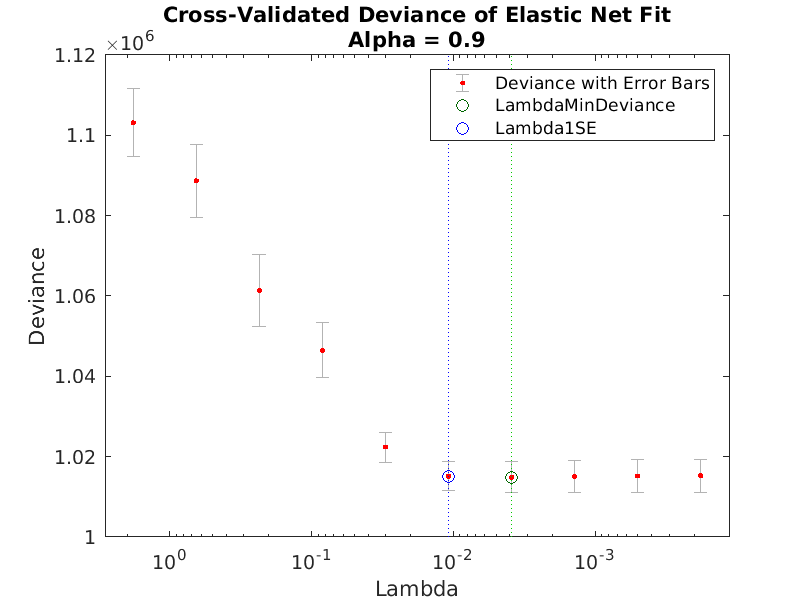

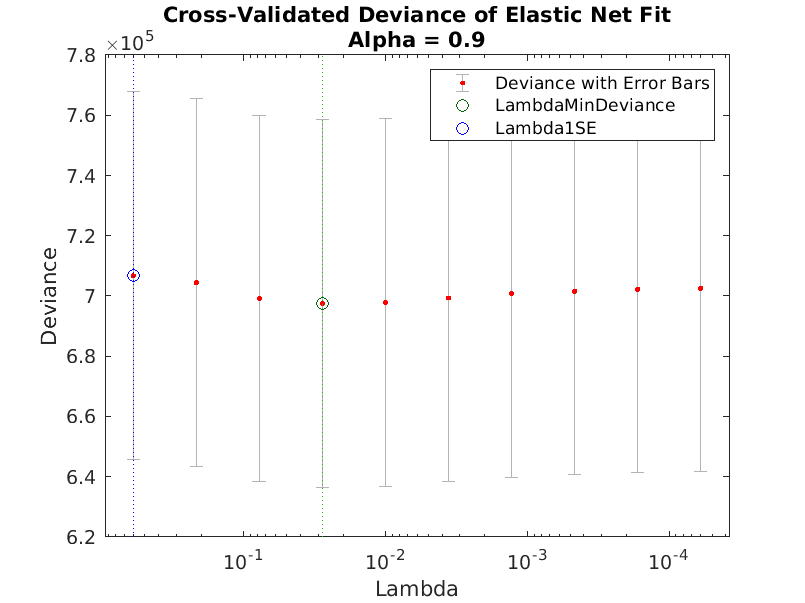

% For test of GLM code

% X = behavior_data_train; %randn(100,20);
% weights = [.4;.2;.3];
% mu = exp(X(:,[5 10 15])*weights + 1);
% y =poissrnd(mu);
% [B,FitInfo] = lassoglm(X,y,'poisson','CV',5);
% idxLamdaMinDeviance =FitInfo.IndexMinDeviance;
% mincoefs = find(B(:,idxLambdaMinDeviance))
% idxLambda1SE = FitInfo.Index1SE;
% min1coefs = find(B(:,idxLambda1SE))
% B0 = FitInfo.Intercept(idxLambdaMinDeviance);
% y_pred = glmval([B0; B(:,idxLambdaMinDeviance)],X,'log');
% B0_ = FitInfo.Intercept(idxLambda1SE);
% y_pred_ = glmval([B0; B(:,idxLambda1SE)],X,'log');
%     SStot = sum((y - mean(y)).^2);
%     SSres = sum((y - y_pred_).^2);
% %     SSres = sum((processed_neural_activity_data_test(:,i_cell) - processed_neural_activity_data_pred{i_cell,1}).^2);
%     R2 = 1 - SSres/SStot
%     figure
%     plot(1:size(X,1),y,1:size(X,1),y_pred,1:size(X,1),y_pred_);
%     title(['Generalized linear model Explained variation' num2str(R2)]);
% %     xlabel('time');
% %     ylabel('normalized neural activity');
%     % ylim([-0.2 1.2]);
%     % xlim([0 max(p_time_temp_transformed)]);
%     legend({'Actual','Predicted MinDeviance', 'Predicted SE'},'Location','northwest');

GLM = cell(size(neural_activity_data,2),2);
mincoefs = cell(size(neural_activity_data,2),2);
processed_neural_activity_data_pred = cell(size(neural_activity_data,2),2);
for i_cell = 1:size(neural_activity_data,2) %10
    if deconvolved ~= true
        if test == true
            [GLM{i_cell,1}, GLM{i_cell,2}] = lassoglm(behavior_data_train,processed_neural_activity_data_train(:,i_cell),'normal','Alpha',0.9,'CV',2,'NumLambda',10); %,'poisson','Alpha',0.9,'CV',5,'NumLambda',100);
        else
            [GLM{i_cell,1}, GLM{i_cell,2}] = lassoglm(behavior_data,processed_neural_activity_data(:,i_cell),'normal','Alpha',0.9,'CV',2,'NumLambda',10); %,'poisson','Alpha',0.9,'CV',5,'NumLambda',100);
        end
    else
        if test == true
            [GLM{i_cell,1}, GLM{i_cell,2}] = lassoglm(behavior_data_train,processed_neural_activity_data_train(:,i_cell),'poisson','Alpha',0.9,'CV',2,'NumLambda',10);
        else
            [GLM{i_cell,1}, GLM{i_cell,2}] = lassoglm(behavior_data,processed_neural_activity_data(:,i_cell),'poisson','Alpha',0.9,'CV',2,'NumLambda',10);
        end
    end

    if i_cell == 1 | i_cell == 2 | i_cell == 3
        lassoPlot(GLM{i_cell,1},GLM{i_cell,2},'plottype','CV'); 
        legend('show') % Show legend
    end
    idxLambdaMinDeviance = GLM{i_cell,2}.IndexMinDeviance;
    % mincoefs = find(GLM{i_cell,1}(:,idxLambdaMinDeviance))
    B0 = GLM{i_cell,2}.Intercept(idxLambdaMinDeviance);
    mincoefs{i_cell,1} = [B0; GLM{i_cell,1}(:,idxLambdaMinDeviance)];
    idxLambda1SE = GLM{i_cell,2}.Index1SE;
    % min1coefs = find(GLM{i_cell,1}(:,idxLambda1SE))
    B0_ = GLM{i_cell,2}.Intercept(idxLambda1SE);
    mincoefs{i_cell,2} = [B0_; GLM{i_cell,1}(:,idxLambda1SE)];
    % processed_neural_activity_data_pred = glmval(mincoefs,behavior_data_test,'log');
    if deconvolved ~= true
        if test == true
            processed_neural_activity_data_pred{i_cell,1} = glmval(mincoefs{i_cell,1},behavior_data_test,'identity'); %,behavior_data_train,'log'); %,behavior_data_test,'log');
            processed_neural_activity_data_pred{i_cell,2} = glmval(mincoefs{i_cell,2},behavior_data_test,'identity'); 
        else
            processed_neural_activity_data_pred{i_cell,1} = glmval(mincoefs{i_cell,1},behavior_data,'identity'); %,behavior_data_train,'log'); %,behavior_data_test,'log');
            processed_neural_activity_data_pred{i_cell,2} = glmval(mincoefs{i_cell,2},behavior_data,'identity'); %,behavior_data_train,'log'); %,behavior_data_test,'log');
        end
    else
        if test == true
            processed_neural_activity_data_pred{i_cell,1} = glmval(mincoefs{i_cell,1},behavior_data_test,'log'); %,behavior_data_test,'log');
            processed_neural_activity_data_pred{i_cell,2} = glmval(mincoefs{i_cell,2},behavior_data_test,'log');  
        else
            processed_neural_activity_data_pred{i_cell,1} = glmval(mincoefs{i_cell,1},behavior_data,'log'); %,behavior_data_test,'log');
            processed_neural_activity_data_pred{i_cell,2} = glmval(mincoefs{i_cell,2},behavior_data,'log'); %,behavior_data_test,'log');
        end
    end
end

% % to test fit to the training data
% 
% for i_cell = 1:size(neural_activity_data,2)
%     processed_neural_activity_data_pred{i_cell,1} = glmval(mincoefs{i_cell,1},behavior_data,'identity'); %,behavior_data_train,'log'); %,behavior_data_test,'log');
%     processed_neural_activity_data_pred{i_cell,2} = glmval(mincoefs{i_cell,2},behavior_data,'identity');
% end
% test = false

% % no CV to reduce computation time
% 
% GLM = cell(size(neural_activity_data,2),2);
% mincoefs = cell(size(neural_activity_data,2),1);
% processed_neural_activity_data_pred = cell(size(neural_activity_data,2),1);
% for i_cell = 1:5
%     if deconvolved ~= true
% %     [GLM{i_cell,1}, GLM{i_cell,2}] = lassoglm(behavior_data_train,processed_neural_activity_data_train(:,i_cell),'normal','Alpha',0.9,'CV',5,'NumLambda',100); %,'poisson','Alpha',0.9,'CV',5,'NumLambda',100);
%         [GLM{i_cell,1}, GLM{i_cell,2}] = lassoglm(behavior_data,processed_neural_activity_data(:,i_cell),'normal','Alpha',0.9,'NumLambda',100); %,'poisson','Alpha',0.9,'CV',5,'NumLambda',100);
%     else
% %         [GLM{i_cell,1}, GLM{i_cell,2}] = lassoglm(behavior_data_train,processed_neural_activity_data_train(:,i_cell),'poisson','Alpha',0.9,'CV',5,'NumLambda',100);
%         [GLM{i_cell,1}, GLM{i_cell,2}] = lassoglm(behavior_data,processed_neural_activity_data(:,i_cell),'poisson','Alpha',0.9,'NumLambda',100);
%     end
% 
%     lassoPlot(GLM{i_cell,1},GLM{i_cell,2}); %,'plottype','CV'); 
%     legend('show') % Show legend
% %     idxLambdaMinDeviance = GLM{i_cell,2};
%     % mincoefs = find(GLM{i_cell,1}(:,idxLambdaMinDeviance))
%     B0 = GLM{i_cell,2}.Intercept;
%     mincoefs{i_cell} = [B0; GLM{i_cell,1}];
% %     idxLambda1SE = GLM{i_cell,2}.Index1SE;
% %     % min1coefs = find(GLM{i_cell,1}(:,idxLambda1SE))
% %     B0_ = GLM{i_cell,2}.Intercept(idxLambda1SE);
% %     mincoefs{i_cell,2} = [B0_; GLM{i_cell,1}(:,idxLambda1SE)];
%     % processed_neural_activity_data_pred = glmval(mincoefs,behavior_data_test,'log');
%     if deconvolved ~= true
%         processed_neural_activity_data_pred{i_cell} = glmval(mincoefs{i_cell},behavior_data,'identity'); %,behavior_data_train,'log'); %,behavior_data_test,'log');
% %         processed_neural_activity_data_pred{i_cell,2} = glmval(mincoefs{i_cell,2},behavior_data,'identity'); %,behavior_data_train,'log'); %,behavior_data_test,'log');
%     else
%         processed_neural_activity_data_pred{i_cell} = glmval(mincoefs{i_cell},behavior_data,'log'); %,behavior_data_test,'log');
% %         processed_neural_activity_data_pred{i_cell,2} = glmval(mincoefs{i_cell,2},behavior_data,'log'); %,behavior_data_test,'log');
%     end
% end

% % try ridge regression
% [GLM{i_cell,1}, GLM{i_cell,2}] = ridge(processed_neural_activity_data(:,i_cell),behavior_data,0.5)

% B0 = GLM{1,2}.Intercept(idxLambdaMinDeviance);
% coef = [B0; GLM{1,1}(:,idxLambdaMinDeviance)]
% processed_neural_activity_data_pred = glmval(coef,behavior_data_test,'log');
% 
% % calculate ^2
% SStot = sum((processed_neural_activity_data_test(:,1) - mean(processed_neural_activity_data_test(:,1))).^2);
% SSres = sum((processed_neural_activity_data_test(:,1) - processed_neural_activity_data_pred).^2);
% R2 = 1 - SSres/SStot;
% fprintf('Explained Variation (R^2) = %.2f\n', R2);

R2 = 0.0345

R2 = 0.0935

R2 = 0.0191

addpath([working_directory  filesep 'Utility' filesep 'Subaxis']);

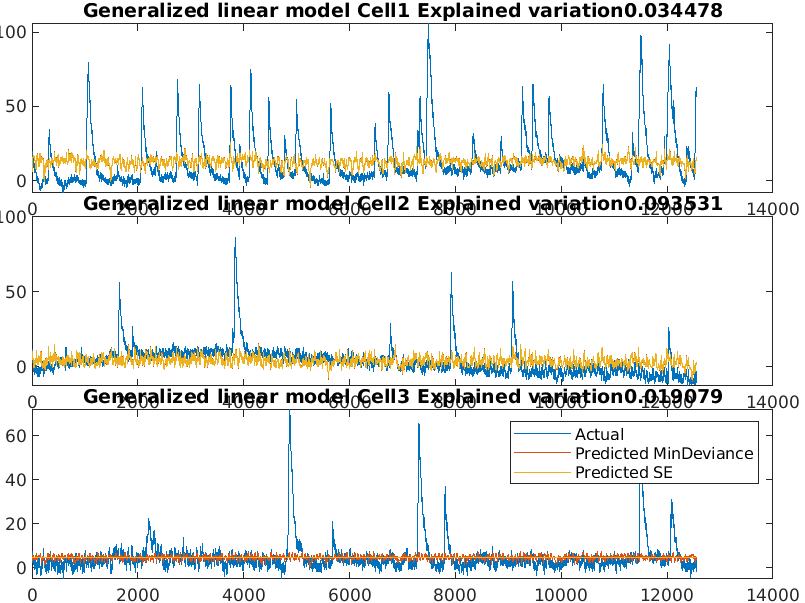

% % plot actual and predicted neural activity
% example_num = 5; % 5;
% figure

% for i_cell = 1:example_num
% %     SStot = sum((processed_neural_activity_data_test(:,i_cell) - mean(processed_neural_activity_data_test(:,i_cell))).^2);
%     SStot = sum((processed_neural_activity_data(:,i_cell) - mean(processed_neural_activity_data(:,i_cell))).^2);
%     SSres = sum((processed_neural_activity_data(:,i_cell) - processed_neural_activity_data_pred{i_cell}).^2);
% %     SSres = sum((processed_neural_activity_data_test(:,i_cell) - processed_neural_activity_data_pred{i_cell,1}).^2);
%     R2 = 1 - SSres/SStot
%     subaxis(example_num,1,i_cell, 'Spacing', 0.02, 'Padding', 0.01, 'Margin', 0.03);
% %     plot(1:length(processed_neural_activity_data_test(:,i_cell)),processed_neural_activity_data_test(:,i_cell),1:length(processed_neural_activity_data_test(:,i_cell)),processed_neural_activity_data_pred{i_cell,1},1:length(processed_neural_activity_data_test(:,i_cell)),processed_neural_activity_data_pred{i_cell,2});
%     plot(1:length(processed_neural_activity_data(:,i_cell)),processed_neural_activity_data(:,i_cell),1:length(processed_neural_activity_data(:,i_cell)),processed_neural_activity_data_pred{i_cell});
%     title(['Generalized linear model Cell' num2str(i_cell) ' Explained variation' num2str(R2)]);
%     
%     ylabel('normalized neural activity');
% %     ylim([-0.2 1.2]);
% %     xlim([0 max(p_time_temp_transformed)]);
% end
% xlabel('time');
%     legend({'Actual','Predicted'},'Location','northeast');
% 
% % figure
% % for i = 1:example_num
% %     subaxis(example_num,1,i, 'Spacing', 0.06, 'Padding', 0.01, 'Margin', 0.03);
% %     b = plot(0:0.1:(size(acc_neural_activity_data,1)-1)/10,acc_neural_activity_data(:,display_start+i));
% % %     title([brain_roi_name(i)], 'FontSize',6);
% %     ylim(ylimit); 
% %     xlim([0 (size(acc_neural_activity_data,1)-1)/10])
% % %     ylabel('neural activity');
% % %     xlabel('time (sec)')
% % end

% plot actual and predicted neural activity

R2 = 0.2179

R2 = 0.8170

R2 = 0.8509

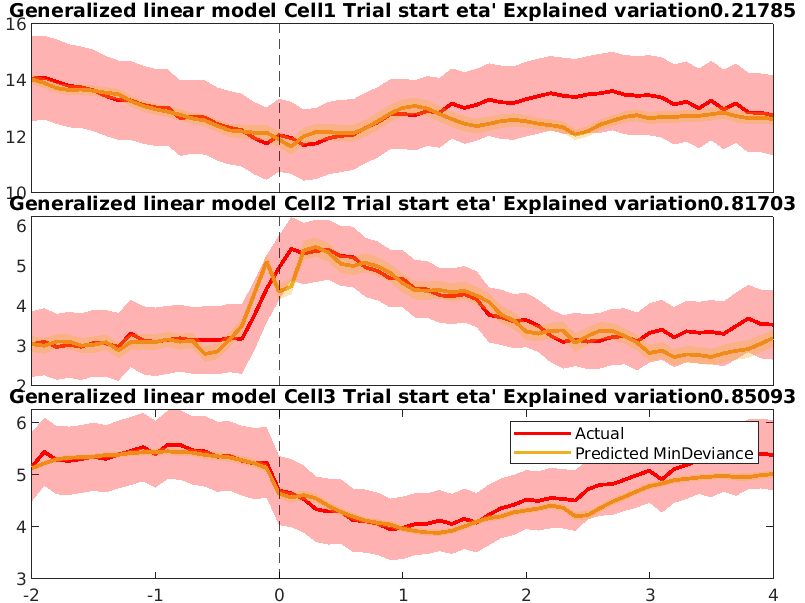

example_num = 3; % 5;
figure
for i_cell = 1:example_num
    if test == true

        SStot = sum((processed_neural_activity_data_test(:,i_cell) - mean(processed_neural_activity_data_test(:,i_cell))).^2);        
        SSres = sum((processed_neural_activity_data_test(:,i_cell) - processed_neural_activity_data_pred{i_cell,1}).^2);
    else
        SStot = sum((processed_neural_activity_data(:,i_cell) - mean(processed_neural_activity_data(:,i_cell))).^2);
        SSres = sum((processed_neural_activity_data(:,i_cell) - processed_neural_activity_data_pred{i_cell,1}).^2);
    end
    R2 = 1 - SSres/SStot
    subaxis(example_num,1,i_cell, 'Spacing', 0.02, 'Padding', 0.01, 'Margin', 0.03);
    if test == true
        plot(1:length(processed_neural_activity_data_test(:,i_cell)),processed_neural_activity_data_test(:,i_cell),1:length(processed_neural_activity_data_test(:,i_cell)),processed_neural_activity_data_pred{i_cell,1},1:length(processed_neural_activity_data_test(:,i_cell)),processed_neural_activity_data_pred{i_cell,2});    
    else
        plot(1:length(processed_neural_activity_data(:,i_cell)),processed_neural_activity_data(:,i_cell),1:length(processed_neural_activity_data(:,i_cell)),processed_neural_activity_data_pred{i_cell,1},1:length(processed_neural_activity_data(:,i_cell)),processed_neural_activity_data_pred{i_cell,2});
    end
    title(['Generalized linear model Cell' num2str(i_cell) ' Explained variation' num2str(R2)]);
    
    ylabel('normalized neural activity');
%     ylim([-0.2 1.2]);
%     xlim([0 max(p_time_temp_transformed)]);
end
xlabel('time');
legend({'Actual','Predicted MinDeviance', 'Predicted SE'},'Location','northeast');
filename = [output_dir Date '_'  Animal,  '_GLM_raw_activity_prediction.png'];
saveas(gcf,filename);     

% figure
% for i = 1:example_num
%     subaxis(example_num,1,i, 'Spacing', 0.06, 'Padding', 0.01, 'Margin', 0.03);
%     b = plot(0:0.1:(size(acc_neural_activity_data,1)-1)/10,acc_neural_activity_data(:,display_start+i));
% %     title([brain_roi_name(i)], 'FontSize',6);
%     ylim(ylimit); 
%     xlim([0 (size(acc_neural_activity_data,1)-1)/10])
% %     ylabel('neural activity');
% %     xlabel('time (sec)')
% end

% TODO: have to reconstruct force act because there is overlap between
% consequensive force act
% force_idx_ori

% if strcmp(clip, 'TrialStart')

R2 = 0.2250

R2 = 0.8009

R2 = 0.9112

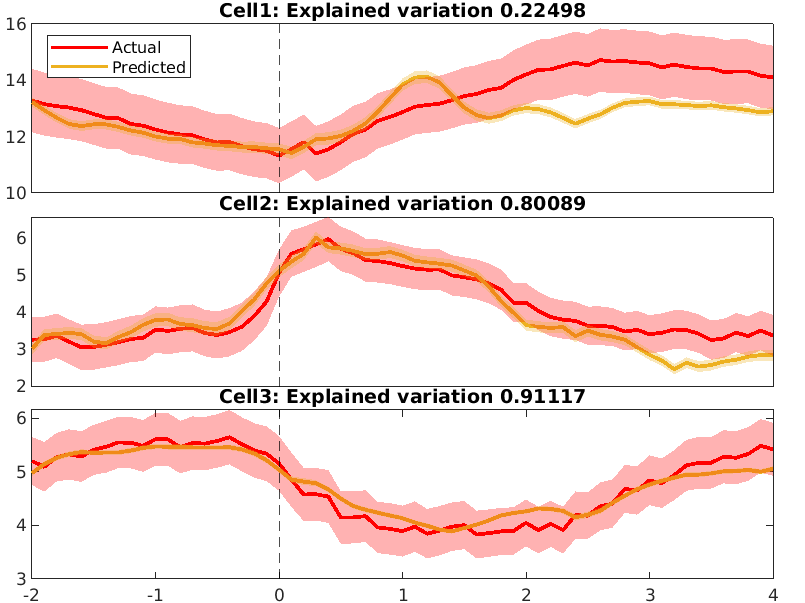

    if test == true
        trial_start_idx_ori_test = trial_start_idx_ori - sum(idxTrain);
        trial_start_idx_test = trial_start_idx - sum(idxTrain);

        trial_start_idx_ori_test(trial_start_idx_ori_test<fps*before_event) = [];
        trial_start_idx_test(trial_start_idx_test<0) = [];
        trial_start_idx_idx   = find_indices(trial_start_idx_ori_test,trial_start_idx_test);
    else
        trial_start_idx_idx   = find_indices(trial_start_idx_ori,trial_start_idx);
    end
    figure
    for i_cell = 1:example_num
        trial_start_act       = zeros(length(trial_start_idx_idx),fps*(before_event+after_event)+1);
        trial_start_act_pred  = zeros(length(trial_start_idx_idx),fps*(before_event+after_event)+1);        
        for j = 1:length(trial_start_idx_idx)
            if strcmp(clip, 'TrialStart')
                if test == true
                    trial_start_act(j,:) = transpose(processed_neural_activity_data_test(trial_start_idx_idx(j)-fps*before_event:trial_start_idx_idx(j)+fps*after_event,i_cell));
                    trial_start_act_pred(j,:) = transpose(processed_neural_activity_data_pred{i_cell,1}(trial_start_idx_idx(j)-fps*before_event:trial_start_idx_idx(j)+fps*after_event));  
                else
                    trial_start_act(j,:) = transpose(processed_neural_activity_data(trial_start_idx_idx(j)-fps*before_event:trial_start_idx_idx(j)+fps*after_event,i_cell));
                    trial_start_act_pred(j,:) = transpose(processed_neural_activity_data_pred{i_cell,1}(trial_start_idx_idx(j)-fps*before_event:trial_start_idx_idx(j)+fps*after_event));
                end
            else
                if test == true
                    trial_start_act(j,:) = transpose(processed_neural_activity_data_test(trial_start_idx_test(trial_start_idx_idx(j))-fps*before_event:trial_start_idx_test(trial_start_idx_idx(j))+fps*after_event,i_cell));
                    trial_start_act_pred(j,:) = transpose(processed_neural_activity_data_pred{i_cell,1}(trial_start_idx_test(trial_start_idx_idx(j))-fps*before_event:trial_start_idx_test(trial_start_idx_idx(j))+fps*after_event));  
                else
                    trial_start_act(j,:) = transpose(processed_neural_activity_data(trial_start_idx(trial_start_idx_idx(j))-fps*before_event:trial_start_idx(trial_start_idx_idx(j))+fps*after_event,i_cell));
                    trial_start_act_pred(j,:) = transpose(processed_neural_activity_data_pred{i_cell,1}(trial_start_idx(trial_start_idx_idx(j))-fps*before_event:trial_start_idx(trial_start_idx_idx(j))+fps*after_event));
                end
            end
        end
%         Force_act = reshape(processed_neural_activity_data(:,i_cell),[fps*(before_event+after_event)+1, []]);
        trial_start_act_SEM = std(trial_start_act,0,1)/sqrt(size(trial_start_act,1));
%         Force_act_pred = reshape(processed_neural_activity_data_pred{i_cell,1},[fps*(before_event+after_event)+1, []]);
        trial_start_act_SEM_pred = std(trial_start_act_pred,0,1)/sqrt(size(trial_start_act_pred,1));
        trial_start_act = mean(trial_start_act,1);
        trial_start_act_pred = mean(trial_start_act_pred,1);

        SStot = sum((trial_start_act - mean(trial_start_act)).^2);
        SSres = sum((trial_start_act - trial_start_act_pred).^2);
        R2 = 1 - SSres/SStot

        subaxis(example_num,1,i_cell, 'Spacing', 0.02, 'Padding', 0.01, 'Margin', 0.03);
        x = -before_event:0.1:after_event;
        x2 = [x, fliplr(x)];
        hold on;
        plot(x,trial_start_act,'r','LineWidth',2);
        plot(x,trial_start_act_pred,'Color',[0.9290 0.6940 0.1250],'LineWidth',2);
        alpha_value = 0.3;
        inBetween1 = [trial_start_act + trial_start_act_SEM, fliplr(trial_start_act - trial_start_act_SEM)];
        fill(x2, inBetween1, 'r', 'EdgeColor', 'none', 'FaceAlpha', alpha_value, 'EdgeAlpha', alpha_value);
        inBetween2 = [trial_start_act_pred + trial_start_act_SEM_pred, fliplr(trial_start_act_pred - trial_start_act_SEM_pred)];
        fill(x2, inBetween2, [0.9290 0.6940 0.1250], 'EdgeColor', 'none', 'FaceAlpha', alpha_value, 'EdgeAlpha', alpha_value);
        xline(0,'--k');
        title(['Generalized linear model Cell' num2str(i_cell) ' Trial start eta'' Explained variation' num2str(R2)]);
        hold off;
        if i_cell ~= example_num
            set(gca,'TickLength',[0 0]);
            set(gca,'XTickLabel',[]);
        end
    end
    xlabel('time');
    legend({'Actual','Predicted MinDeviance'},'Location','northeast');
    filename = [output_dir Date '_'  Animal, '_GLM_trial_start_ETA_prediction.png'];
    saveas(gcf,filename);   
% elseif strcmp(clip, 'Force')
    if test == true
        force_idx_ori_test = force_idx_ori - sum(idxTrain);
        force_idx_test = force_idx - sum(idxTrain);
        force_idx_ori_test(force_idx_ori_test<fps*before_event) = [];
        force_idx_test(force_idx_test<0) = [];
        force_idx_idx   = find_indices(force_idx_ori_test,force_idx_test);
    else
        force_idx_idx   = find_indices(force_idx_ori,force_idx);
    end
    figure
    for i_cell = 1:example_num
        Force_act       = zeros(length(force_idx_idx),fps*(before_event+after_event)+1);
        Force_act_pred  = zeros(length(force_idx_idx),fps*(before_event+after_event)+1);        
        for j = 1:length(force_idx_idx)
            if strcmp(clip, 'Force')
                if test == true
                    Force_act(j,:) = transpose(processed_neural_activity_data_test(force_idx_idx(j)-fps*before_event:force_idx_idx(j)+fps*after_event,i_cell));
                    Force_act_pred(j,:) = transpose(processed_neural_activity_data_pred{i_cell,1}(force_idx_idx(j)-fps*before_event:force_idx_idx(j)+fps*after_event));  
                else                
                    Force_act(j,:) = transpose(processed_neural_activity_data(force_idx_idx(j)-fps*before_event:force_idx_idx(j)+fps*after_event,i_cell));
                    Force_act_pred(j,:) = transpose(processed_neural_activity_data_pred{i_cell,1}(force_idx_idx(j)-fps*before_event:force_idx_idx(j)+fps*after_event));
                end
            else
                if test == true
                    Force_act(j,:) = transpose(processed_neural_activity_data_test(force_idx_test(force_idx_idx(j))-fps*before_event:force_idx_test(force_idx_idx(j))+fps*after_event,i_cell));
                    Force_act_pred(j,:) = transpose(processed_neural_activity_data_pred{i_cell,1}(force_idx_test(force_idx_idx(j))-fps*before_event:force_idx_test(force_idx_idx(j))+fps*after_event));  
                else
                    Force_act(j,:) = transpose(processed_neural_activity_data(force_idx(force_idx_idx(j))-fps*before_event:force_idx(force_idx_idx(j))+fps*after_event,i_cell));
                    Force_act_pred(j,:) = transpose(processed_neural_activity_data_pred{i_cell,1}(force_idx(force_idx_idx(j))-fps*before_event:force_idx(force_idx_idx(j))+fps*after_event));
                end
            end
        end
%         Force_act = reshape(processed_neural_activity_data(:,i_cell),[fps*(before_event+after_event)+1, []]);
        Force_act_SEM = std(Force_act,0,1)/sqrt(size(Force_act,1));
%         Force_act_pred = reshape(processed_neural_activity_data_pred{i_cell,1},[fps*(before_event+after_event)+1, []]);

centroidX =     66
    10
    61
    34
    62
    56
    52
    69
    45
    54


        Force_act_SEM_pred = std(Force_act_pred,0,1)/sqrt(size(Force_act_pred,1));
        Force_act = mean(Force_act,1);
        Force_act_pred = mean(Force_act_pred,1);

        SStot = sum((Force_act - mean(Force_act)).^2);
        SSres = sum((Force_act - Force_act_pred).^2);
        R2 = 1 - SSres/SStot

        subaxis(example_num,1,i_cell, 'Spacing', 0.02, 'Padding', 0.01, 'Margin', 0.03);
        x = -before_event:0.1:after_event;
        x2 = [x, fliplr(x)];
        hold on;
        plot(x,Force_act,'r','LineWidth',2);
        plot(x,Force_act_pred,'Color',[0.9290 0.6940 0.1250],'LineWidth',2);
        alpha_value = 0.3;
        inBetween1 = [Force_act + Force_act_SEM, fliplr(Force_act - Force_act_SEM)];
        fill(x2, inBetween1, 'r', 'EdgeColor', 'none', 'FaceAlpha', alpha_value, 'EdgeAlpha', alpha_value);
        inBetween2 = [Force_act_pred + Force_act_SEM_pred, fliplr(Force_act_pred - Force_act_SEM_pred)];
        fill(x2, inBetween2, [0.9290 0.6940 0.1250], 'EdgeColor', 'none', 'FaceAlpha', alpha_value, 'EdgeAlpha', alpha_value);
        xline(0,'--k');
%         title(['Generalized linear model Cell' num2str(i_cell) ' Force eta'' Explained variation' num2str(R2)]);
        title(['Cell' num2str(i_cell) ': Explained variation ' num2str(R2)]);
%         title(['R2 = ' num2str(R2)]);
        hold off;
        if i_cell ~= example_num
            set(gca,'TickLength',[0 0]);
            set(gca,'XTickLabel',[]);
        end
        if i_cell == 1
            legend({'Actual','Predicted'},'Location','northwest');
        end
    end
    xlabel('time');
    filename = [output_dir Date '_'  Animal, '_GLM_force_ETA_prediction.png'];
    saveas(gcf,filename);
    %     legend({'Actual','Predicted MinDeviance'},'Location','northeast');
%     legend({'Actual','Predicted'},'Location','northeast');
% end

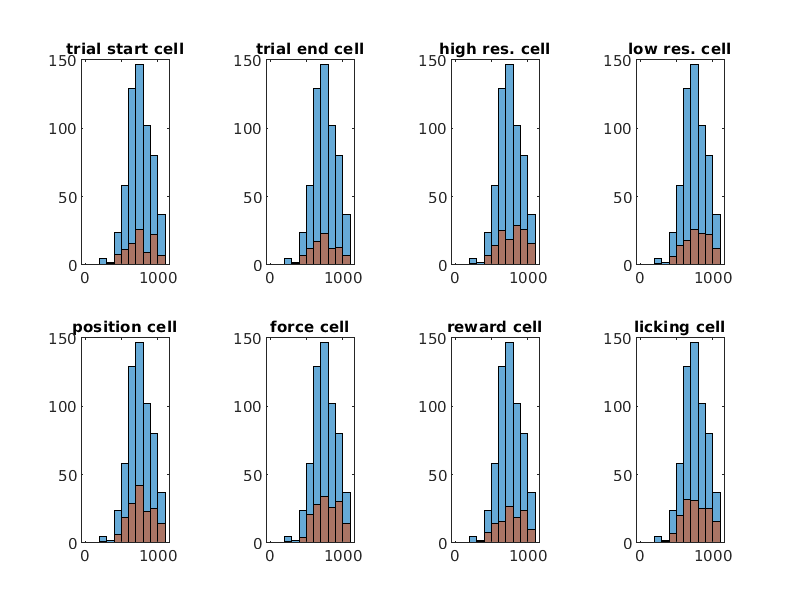

% % before_event = 2; %1;
% % after_event  = 4; %2;

% force        = behavior_neural_time(:,7);
% force_idx    = find(force > force_thr);
% cur_RecICA{block} = zeros(example_num,(before_event+after_event)*fps/1000+1);
% if timepoints(block,1)<1
%     before_start = - timepoints(block,1);
%     cur_RecICA{block}(:,1:before_start+1) = NaN;
%     cur_RecICA{block}(:,before_start+2:(before+after)*fps/1000+1) = RecICA_Temp{block}(:,1:timepoints(block,2));
% elseif timepoints(block,2)>size(RecICA_Temp{block},2)
%     after_end = timepoints(block,2) - size(RecICA_Temp{block},2);
%     cur_RecICA{block}(:,(before+after)*fps/1000+1-after_end:(before+after)*fps/1000+1) = NaN;
%     cur_RecICA{block}(:,1:(before+after)*fps/1000-after_end) = RecICA_Temp{block}(:,timepoints(block,1):size(RecICA_Temp{block},2));
% else
%     cur_RecICA{block} = RecICA_Temp{block}(:,timepoints(block,1):timepoints(block,2));
% end

% [GLM{1,1}, GLM{1,2}] = lassoglm(behavior_data,processed_neural_activity_data(:,1),'poisson','Alpha',0.9,'CV',5,'NumLambda',100);
% lassoPlot(GLM{1,1},GLM{1,2},'plottype','CV'); 
% legend('show') % Show legend
% idxLambdaMinDeviance = GLM{1,2}.IndexMinDeviance;
% mincoefs = find(GLM{1,1}(:,idxLambdaMinDeviance))
% idxLambda1SE = GLM{1,2}.Index1SE;
% min1coefs = find(GLM{1,1}(:,idxLambda1SE))

% lassoPlot(GLM{1,1},GLM{1,2},'plottype','CV'); 
% legend('show') % Show legend

% idxLambdaMinDeviance = GLM{1,2}.IndexMinDeviance;
% mincoefs = find(GLM{1,1}(:,idxLambdaMinDeviance))

% idxLambda1SE = GLM{1,2}.Index1SE;
% min1coefs = find(GLM{1,1}(:,idxLambda1SE))

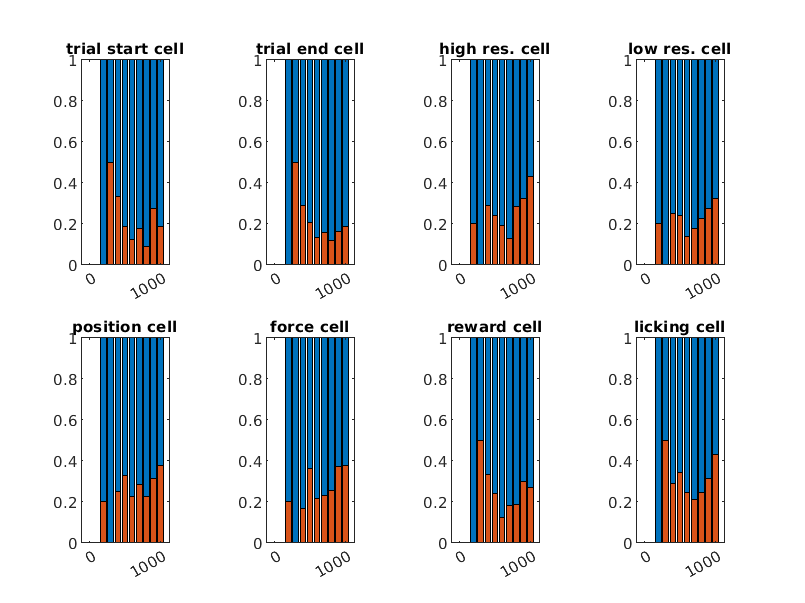

 % trial_start_conv, trial_end_conv, resistance_high_conv,
 % resistance_low_conv, position_conv, force_conv, reward_conv,
 % licking_conv
 % 1-7,8-14,15-21,22-28,29-34,35-41,42-48,49-55
 % old:1-5,6-10,11-15,16-20,21-26,27-31,32-38
 % use Lambda1SE
 trial_start_cell = zeros(size(neural_activity_data,2),1);
 trial_end_cell = zeros(size(neural_activity_data,2),1);

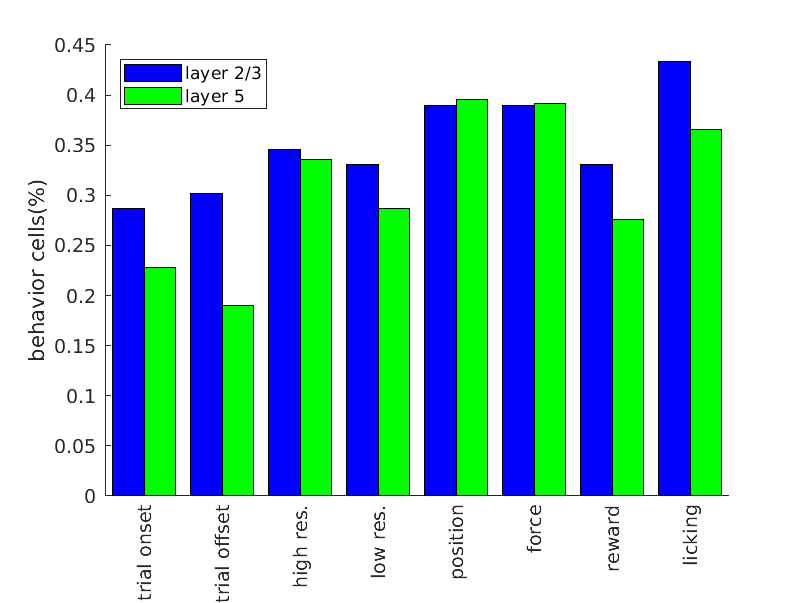

 resistance_high_cell = zeros(size(neural_activity_data,2),1);
 resistance_low_cell = zeros(size(neural_activity_data,2),1);
 position_cell = zeros(size(neural_activity_data,2),1);
 force_cell = zeros(size(neural_activity_data,2),1);
 reward_cell = zeros(size(neural_activity_data,2),1);
 licking_cell = zeros(size(neural_activity_data,2),1);
 state_value_cell = zeros(size(neural_activity_data,2),1);
 action_value_cell = zeros(size(neural_activity_data,2),1);

 for i_cell = 1:size(neural_activity_data,2)
    if sum(mincoefs{i_cell,2}(2:8)) > 0
        trial_start_cell(i_cell) = 1;
    end
    if sum(mincoefs{i_cell,2}(9:15)) > 0
        trial_end_cell(i_cell) = 1;
    end
    if sum(mincoefs{i_cell,2}(16:22)) > 0
        resistance_high_cell(i_cell) = 1;
    end
    if sum(mincoefs{i_cell,2}(23:29)) > 0
        resistance_low_cell(i_cell) = 1;
    end
    if sum(mincoefs{i_cell,2}(30:35)) > 0
        position_cell(i_cell) = 1;
    end
    if sum(mincoefs{i_cell,2}(36:42)) > 0
        force_cell(i_cell) = 1;
    end
    if sum(mincoefs{i_cell,2}(43:49)) > 0
        reward_cell(i_cell) = 1;
    end
    if sum(mincoefs{i_cell,2}(50:56)) > 0
        licking_cell(i_cell) = 1;
    end
    if state_action_value == true
        if sum(mincoefs{i_cell,2}(57:66)) > 0
            state_value_cell(i_cell) = 1;
        end
        if sum(mincoefs{i_cell,2}(67:96)) > 0
            action_value_cell(i_cell) = 1;
        end
    end

end
if state_action_value == true
    cell_representations = [trial_start_cell, trial_end_cell, resistance_high_cell, resistance_low_cell, position_cell, force_cell, reward_cell, licking_cell, state_value_cell, action_value_cell];
else
    cell_representations = [trial_start_cell, trial_end_cell, resistance_high_cell, resistance_low_cell, position_cell, force_cell, reward_cell, licking_cell];
end

% % neural_traits_table = readtable(['D:\Doya_rotation' filesep Date '_' Animal '_' Key filesep 'cell traces-props.csv']);%,'NumHeaderLines',1);
% neural_traits_table = readtable([data_folder filesep 'cell_traces-props.csv']); %Linux
% % centroidY = neural_traits_table.('CentroidY')
% centroidX = neural_traits_table.('CentroidX') % corresponding cortical depth

% if image_reverse == 0;
%     depth = 1100 - centroidX*900/(1280/4);   %arc247: acc_neural_property_data(:,4)*1000/(1066/4); %tph189,tph199: 1100 - acc_neural_property_data(:,4)*1000/(1066/4); 
% else
%     depth = centroidX*900/(1280/4);
% %     depth = 1100 - acc_neural_property_data(:,4)*1000/(1066/4);   %arc247: acc_neural_property_data(:,4)*1000/(1066/4); %tph189,tph199: 1100 - acc_neural_property_data(:,4)*1000/(1066/4); 
% end

% plot the relation between position and representaion of each variables
if state_action_value == true
    figure
    addpath([working_directory filesep 'Utility' filesep 'Subaxis']);
    titles = {'trial start cell', 'trial end cell', 'high res. cell', 'low res. cell', 'position cell', 'force cell', 'reward cell', 'licking cell', 'state val. cell', 'action val. cell'};
    for i = 1:10
        subaxis(2,5,i, 'Spacing', 0.04, 'Padding', 0.02, 'Margin', 0.04);
        edges = [0:100:1100];
        h1 = histogram(depth,edges); %centroidY);
        hold on
        h2 = histogram(depth(cell_representations(:,i)==1),edges); %centroidY(cell_representations(:,i)==1));
        title(titles(i), 'FontSize',8);
%         xlabel('cell depth');
%         ylabel('cell number');
    end
else
    figure
    addpath([working_directory filesep 'Utility' filesep 'Subaxis']);
    titles = {'trial start cell', 'trial end cell', 'high res. cell', 'low res. cell', 'position cell', 'force cell', 'reward cell', 'licking cell'};
    for i = 1:8
        subaxis(2,4,i, 'Spacing', 0.04, 'Padding', 0.04, 'Margin', 0.06);
        edges = [0:100:1100];
        h1 = histogram(depth,edges); %centroidY);
        hold on
        h2 = histogram(depth(cell_representations(:,i)==1),edges); %centroidY(cell_representations(:,i)==1));
        title(titles(i), 'FontSize',8);
%         xlabel('cell depth');
%         ylabel('cell number');
    end
end
filename = [output_dir Date '_'  Animal, '_encoding_cell_distribution.png'];
saveas(gcf,filename);

% plot ratio
if state_action_value == true
    figure
    addpath([working_directory filesep 'Utility' filesep 'Subaxis']);
    titles = {'trial start cell', 'trial end cell', 'high res. cell', 'low res. cell', 'position cell', 'force cell', 'reward cell', 'licking cell', 'state val. cell', 'action val. cell'};
    for i = 1:10
        subaxis(2,5,i, 'Spacing', 0.04, 'Padding', 0.02, 'Margin', 0.04);
        edges = [0:100:1100];
        h1 = histcounts(depth,edges); %centroidY);
        h2 = histcounts(depth(cell_representations(:,i)==1),edges); %centroidY(cell_representations(:,i)==1));
        h_ratio = h2 ./ h1;
        bar(edges(1:end-1), h1 ./ h1,'FaceColor','cyan');
        hold on

Unrecognized function or variable 'state_state_value_cell'.

        bar(edges(1:end-1), h_ratio,'FaceColor','magenta');
        ylim([0 1]);        
        title(titles(i), 'FontSize',8);
%         xlabel('cell depth');
%         ylabel('cell number');
    end
else
    figure
    addpath([working_directory filesep 'Utility' filesep 'Subaxis']);
    titles = {'trial start cell', 'trial end cell', 'high res. cell', 'low res. cell', 'position cell', 'force cell', 'reward cell', 'licking cell'};
    for i = 1:8
        subaxis(2,4,i, 'Spacing', 0.04, 'Padding', 0.04, 'Margin', 0.06);
        edges = [0:100:1100];
        h1 = histcounts(depth,edges); %centroidY);
        h2 = histcounts(depth(cell_representations(:,i)==1),edges); %centroidY(cell_representations(:,i)==1));
        h_ratio = h2 ./ h1;
        bar(edges(1:end-1), h1 ./ h1); %,'FaceColor','cyan');
        xticks([0 1000]);
        hold on
        bar(edges(1:end-1), h_ratio); %,'FaceColor','magenta');
        ylim([0 1]);
        title(titles(i), 'FontSize',8);
%         xlabel('cell depth');
%         ylabel('cell number');
    end
end
filename = [output_dir Date '_'  Animal, '_encoding_cell_ratio.png'];
saveas(gcf,filename);

if state_action_value == true
    layer_cell_representations = zeros(10,2);
    for i = 1:10
        layer_cell_representations(i,:) = [sum(cell_representations(:,i)&pointAreas)/sum(pointAreas),sum(cell_representations(:,i)&(~pointAreas))/sum(~pointAreas)];
    end
    conditions = 1:10;
    figure;
    hold on;
    bar(conditions - 0.2, layer_cell_representations(:,1), 'g','BarWidth',0.4);
    bar(conditions + 0.2, layer_cell_representations(:,2), 'b','BarWidth',0.4);
    
    legend('layer 2/3', 'layer 5', 'Location', 'northwest');
    
    ylabel('Behavior cells(%)');
    xlabels = {'trial onset', 'trial offset', 'high res.', 'low res.', 'position', 'force', 'reward', 'licking', 'state value', 'action value'};
    xticks(conditions);
    xticklabels(xlabels);
    xlim([0.5, 10.5]);    
    xtickangle(90);
else
    layer_cell_representations = zeros(8,2);
    for i = 1:8
        layer_cell_representations(i,:) = [sum(cell_representations(:,i)&pointAreas)/sum(pointAreas),sum(cell_representations(:,i)&(~pointAreas))/sum(~pointAreas)];
    end
    conditions = 1:8;
    figure;
    hold on;
    bar(conditions - 0.2, layer_cell_representations(:,1), 'g','BarWidth',0.4);
    bar(conditions + 0.2, layer_cell_representations(:,2), 'b','BarWidth',0.4);
    
    legend('layer 2/3', 'layer 5', 'Location', 'northwest');
    
    ylabel('Behavior cells(%)');
    xlabels = {'trial onset', 'trial offset', 'high res.', 'low res.', 'position', 'force', 'reward', 'licking'};
    xticks(conditions);
    xticklabels(xlabels);
    xlim([0.5, 8.5]);    
    xtickangle(90);
end
filename = [output_dir Date '_'  Animal, '_encoding_cell_ratio_layer_compare.png'];
saveas(gcf,filename);

% GLM_230210 = GLM;

% save table as mat file
% save(['D:\Doya_rotation' filesep Date '_' Animal '_' Key filesep Animal '_behavior_' Date '_' Key '.mat'], 'GLM'); % 'GLM_230210');
save([data_folder filesep Animal '_behavior_' Date '_' Key '.mat'], 'GLM', '-append');

% plot pie graph
if state_action_value == true
    state_state_value_cell = (resistance_high_cell|resistance_low_cell|position_cell)&state_value_cell;
    action_action_value_cell = force_cell&action_value_cell;
    ssv_aav_cell = state_state_value_cell & action_action_value_cell;
    neither_num = length(ssv_aav_cell)+nnz(ssv_aav_cell)-nnz(state_state_value_cell)-nnz(action_action_value_cell);
    data = [nnz(ssv_aav_cell),nnz(state_state_value_cell),nnz(action_action_value_cell),neither_num];
    labels = {['state and action value'],['state value'],['action value'], ['neither']};

    figure
    p = pie(data); %,labels); 
    title({['Ratio of value neurons (n=' num2str(sum(data)) ')']});
    pText = findobj(p,'Type','text');
    percentValues = get(pText,'String');
    txt = {['(' num2str(data(1)) ')']; ['(' num2str(data(2)) ')']; ['(' num2str(data(3)) ')']; ['(' num2str(data(4)) ')']};
    combinedtxt = strcat(percentValues,txt);
    pText(1).String = combinedtxt(1); pText(2).String = combinedtxt(2); 
    pText(3).String = combinedtxt(3); pText(4).String = combinedtxt(4); 
    legend(labels,'Location','southoutside');
    filename = [output_dir Date '_'  Animal, '_state_action_value_cells_pie.png'];
    saveas(gcf,filename);
end

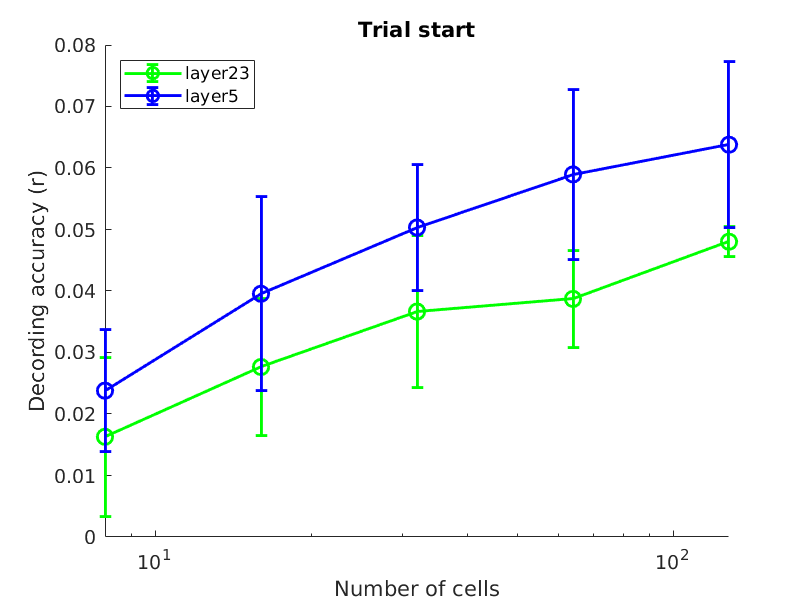

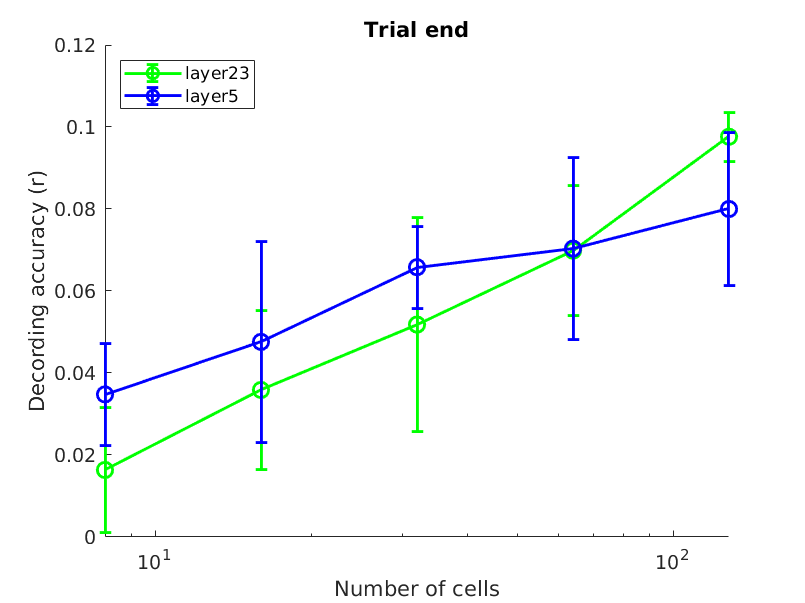

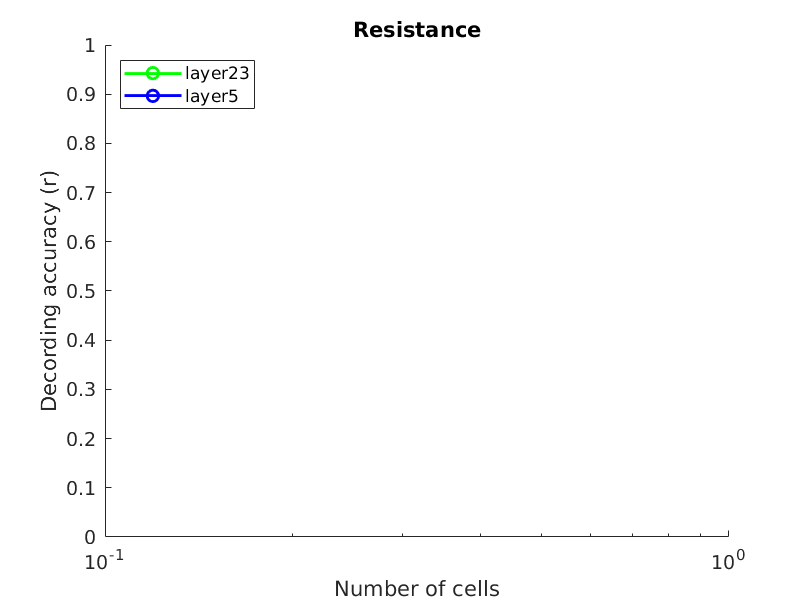

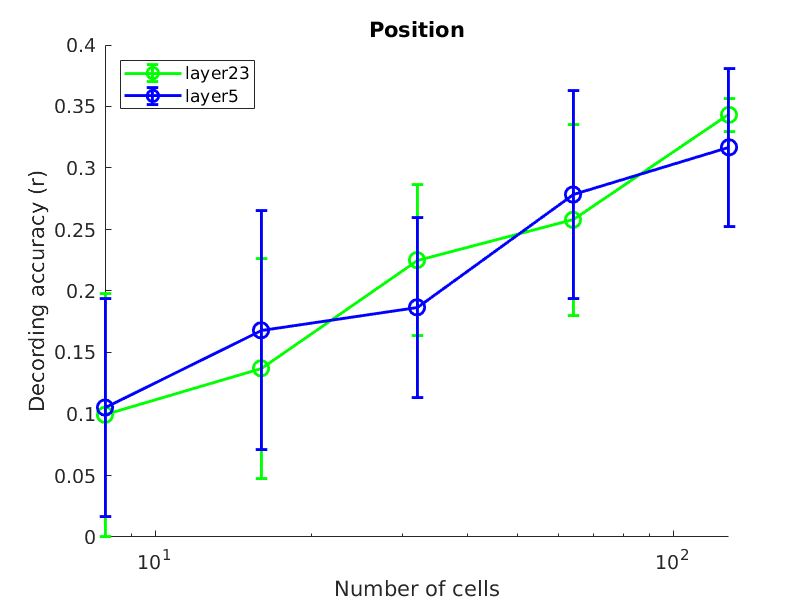

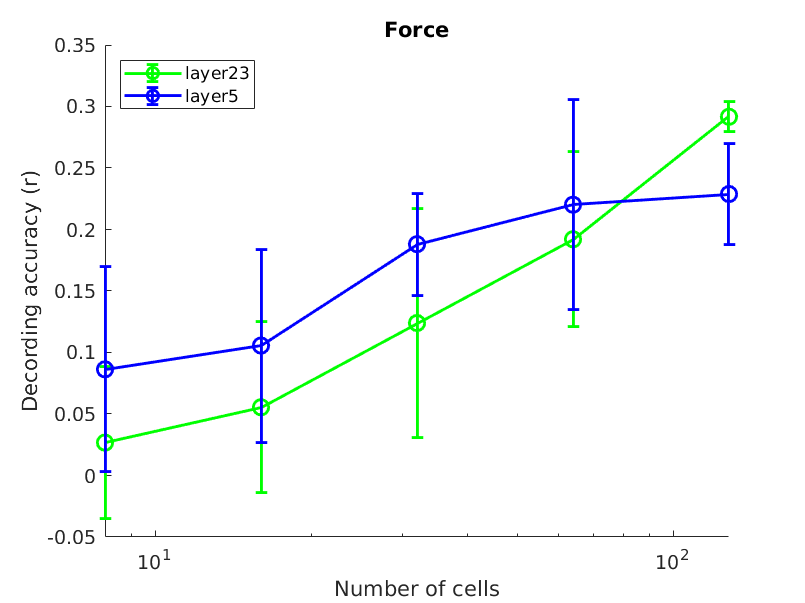

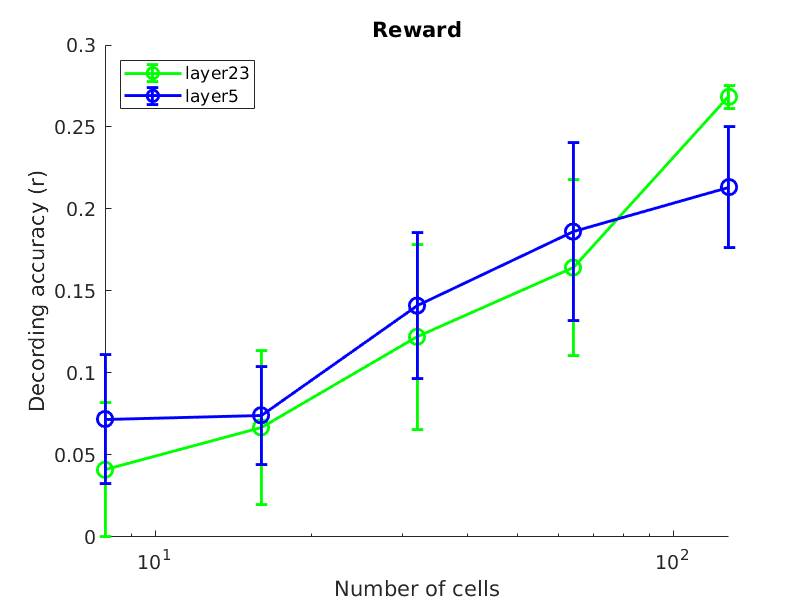

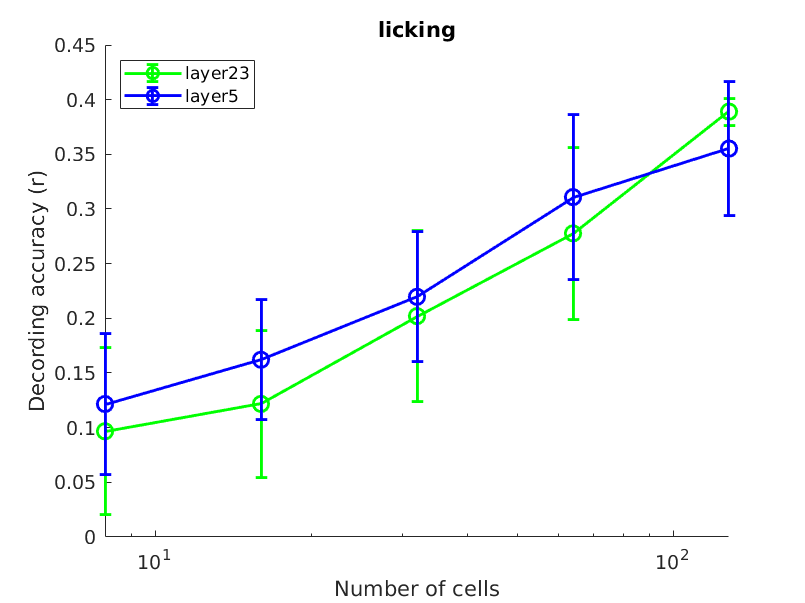

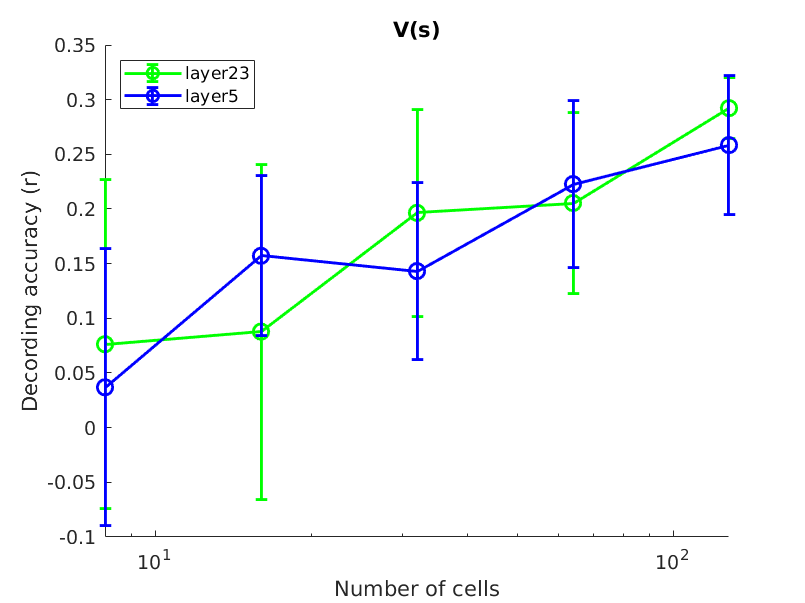

%% TODO: support of sig_cell && layer
if layer == true & state_action_value == true
%     layer23_cells = acc_neural_activity_data(:,find(pointAreas == 1));
%     layer5_cells  = acc_neural_activity_data(:,find(pointAreas == 0));

    state_state_value_cells = {state_state_value_cell(find(pointAreas == 1)), state_state_value_cell(find(pointAreas == 0))};
    action_action_value_cells = {action_action_value_cell(find(pointAreas == 1)), action_action_value_cell(find(pointAreas == 0))};
    ssv_aav_cells = {ssv_aav_cell(find(pointAreas == 1)), ssv_aav_cell(find(pointAreas == 0))};
    neither_num23 = sum(pointAreas)+nnz(ssv_aav_cells{1})-nnz(state_state_value_cells{1})-nnz(action_action_value_cells{1});
    neither_num5  = length(pointAreas)-sum(pointAreas)+nnz(ssv_aav_cells{2})-nnz(state_state_value_cells{2})-nnz(action_action_value_cells{2}); 

    data23 = [nnz(ssv_aav_cells{1}),nnz(state_state_value_cells{1}),nnz(action_action_value_cells{1}),neither_num23];
    labels = {['state and action value'],['state value'],['action value'], ['neither']};
    figure
    p = pie(data23); %, labels); 
%     title({['Layer2/3: Ratio of value neurons (n=' num2str(sum(data23)) ')']});
    pText = findobj(p,'Type','text');
    percentValues = get(pText,'String');
    txt = {['(' num2str(data23(1)) ')']; ['(' num2str(data23(2)) ')']; ['(' num2str(data23(3)) ')']; ['(' num2str(data23(4)) ')']};
    combinedtxt = strcat(percentValues,txt);
    pText(1).String = combinedtxt(1); pText(2).String = combinedtxt(2); 
    pText(3).String = combinedtxt(3); pText(4).String = combinedtxt(4); 
    legend(labels,'Location','southoutside');    
    filename = [output_dir Date '_'  Animal, '_layer23_state_action_value_cells_pie.png'];
    saveas(gcf,filename);    

    data5 = [nnz(ssv_aav_cells{2}),nnz(state_state_value_cells{2}),nnz(action_action_value_cells{2}),neither_num5];

    labels = {['state and action value'],['state value'],['action value'], ['neither']};
    figure
    p = pie(data5); %, labels); %depth,'filled');
%     title({['Layer5: Ratio of value neurons (n=' num2str(sum(data5)) ')']});
    pText = findobj(p,'Type','text');
    percentValues = get(pText,'String');
    txt = {['(' num2str(data5(1)) ')']; ['(' num2str(data5(2)) ')']; ['(' num2str(data5(3)) ')']; ['(' num2str(data5(4)) ')']};
    combinedtxt = strcat(percentValues,txt);
    pText(1).String = combinedtxt(1); pText(2).String = combinedtxt(2); 
    pText(3).String = combinedtxt(3); pText(4).String = combinedtxt(4); 
    legend(labels,'Location','southoutside');    
    filename = [output_dir Date '_'  Animal '_layer5_state_action_value_cells_pie.png'];
    saveas(gcf,filename);     
end

% z test to see difference of ratio (ligh reward activated vs low reward activated)
% [h, p, ci, stats] = proptest(sum(ssv_aav_cells{1}),length(ssv_aav_cells{1}),sum(ssv_aav_cells{2}),length(ssv_aav_cells{2}),'Alpha',0.05,'Tail','both');
% print(['h:' num2str(h) ' p:' num2str(p) ' ci:' num2str(ci) ' stats:' num2str(stats)]);
% print(['state:' num2str(h) ' p:' num2str(p) ' ci:' num2str(ci) ' stats:' num2str(stats)]);

% kari_x = [1 1 0 0 0 0 0 0 0 0];
% kari_y = [1 1 1 1 1 0 0 0 0 0];
% [h, p, ci, stats] = ztest(kari_x,sum(kari_x),kari_y,sum(kari_y),'Alpha',0.05,'Tail','both');
% print(['h:' num2str(h) ' p:' num2str(p) ' ci:' num2str(ci) ' stats:' num2str(stats)]);

Trial start


2-way ANOVA:


    {'Source'      }    {'Sum Sq.'}    {'d.f.'}    {'Singular?'}    {'Mean Sq.'  }    {'F'       }    {'Prob>F'    }
    {'layer'       }    {[ 0.0048]}    {[   1]}    {[        0]}    {[    0.0048]}    {[ 36.0254]}    {[3.6266e-08]}
    {'num_of_cells'}    {[ 0.0156]}    {[   4]}    {[        0]}    {[    0.0039]}    {[ 29.4981]}    {[6.8216e-16]}
    {'Error'       }    {[ 0.0125]}    {[  94]}    {[        0]}    {[1.3252e-04]}    {0×0 double}    {0×0 double  }
    {'Total'       }    {[ 0.0329]}    {[  99]}    {[        0]}    {0×0 double  }    {0×0 double}    {0×0 double  }



Tukey multi comparison:


                  Group1                                 Group2                   Lower Limit       A-B        Upper Limit     P-value  
    ___________________________________    ___________________________________    ___________    __________    ___________    __________

    {'layer=L23,num_of_cells=8cells'  }    {'layer=L5,num_of_cells=8cells'   }      -0.02128      -0.013819     -0.0063571    1.5841e-06
    {'layer=L23,num_of_cells=8cells'  }    {'layer=L23,num_of_cells=16cells' }     -0.025352      -0.013554     -0.0017558      0.011837
    {'layer=L23,num_of_cells=8cells'  }    {'layer=L5,num_of_cells=16cells'  }     -0.041332      -0.027373      -0.013413    3.2405e-07
    {'layer=L23,num_of_cells=8cells'  }    {'layer=L23,num_of_cells=32cells' }     -0.035242      -0.023444   

Trial end


2-way ANOVA:


    {'Source'      }    {'Sum Sq.'   }    {'d.f.'}    {'Singular?'}    {'Mean Sq.'  }    {'F'       }    {'Prob>F'    }
    {'layer'       }    {[7.3046e-04]}    {[   1]}    {[        0]}    {[7.3046e-04]}    {[  2.0352]}    {[    0.1570]}
    {'num_of_cells'}    {[    0.0482]}    {[   4]}    {[        0]}    {[    0.0120]}    {[ 33.5508]}    {[2.2535e-17]}
    {'Error'       }    {[    0.0337]}    {[  94]}    {[        0]}    {[3.5891e-04]}    {0×0 double}    {0×0 double  }
    {'Total'       }    {[    0.0826]}    {[  99]}    {[        0]}    {0×0 double  }    {0×0 double}    {0×0 double  }



Tukey multi comparison:


                  Group1                                 Group2                   Lower Limit       A-B        Upper Limit     P-value  
    ___________________________________    ___________________________________    ___________    __________    ___________    __________

    {'layer=L23,num_of_cells=8cells'  }    {'layer=L5,num_of_cells=8cells'   }     -0.017685     -0.0054054     0.0068746        0.91574
    {'layer=L23,num_of_cells=8cells'  }    {'layer=L23,num_of_cells=16cells' }     -0.035575      -0.016159     0.0032578        0.19009
    {'layer=L23,num_of_cells=8cells'  }    {'layer=L5,num_of_cells=16cells'  }     -0.044538      -0.021564     0.0014098       0.084727
    {'layer=L23,num_of_cells=8cells'  }    {'layer=L23,num_of_cells=32cells' }     -0.052657      -0.033241   

Position


2-way ANOVA:


    {'Source'      }    {'Sum Sq.'   }    {'d.f.'}    {'Singular?'}    {'Mean Sq.'  }    {'F'       }    {'Prob>F'    }
    {'layer'       }    {[5.4981e-05]}    {[   1]}    {[        0]}    {[5.4981e-05]}    {[  0.0090]}    {[    0.9245]}
    {'num_of_cells'}    {[    0.6535]}    {[   4]}    {[        0]}    {[    0.1634]}    {[ 26.8074]}    {[7.5718e-15]}
    {'Error'       }    {[    0.5729]}    {[  94]}    {[        0]}    {[    0.0061]}    {0×0 double}    {0×0 double  }
    {'Total'       }    {[    1.2265]}    {[  99]}    {[        0]}    {0×0 double  }    {0×0 double}    {0×0 double  }



Tukey multi comparison:


                  Group1                                 Group2                   Lower Limit       A-B       Upper Limit     P-value  
    ___________________________________    ___________________________________    ___________    _________    ___________    __________

    {'layer=L23,num_of_cells=8cells'  }    {'layer=L5,num_of_cells=8cells'   }     -0.049121      0.001483      0.052087              1
    {'layer=L23,num_of_cells=8cells'  }    {'layer=L23,num_of_cells=16cells' }      -0.13032     -0.050311        0.0297        0.57505
    {'layer=L23,num_of_cells=8cells'  }    {'layer=L5,num_of_cells=16cells'  }       -0.1435     -0.048828      0.045842        0.80829
    {'layer=L23,num_of_cells=8cells'  }    {'layer=L23,num_of_cells=32cells' }      -0.18366      -0.10365     -0.0

Force


2-way ANOVA:


    {'Source'      }    {'Sum Sq.'}    {'d.f.'}    {'Singular?'}    {'Mean Sq.'}    {'F'       }    {'Prob>F'    }
    {'layer'       }    {[ 0.0194]}    {[   1]}    {[        0]}    {[  0.0194]}    {[  3.8591]}    {[    0.0524]}
    {'num_of_cells'}    {[ 0.5778]}    {[   4]}    {[        0]}    {[  0.1444]}    {[ 28.7820]}    {[1.2792e-15]}
    {'Error'       }    {[ 0.4717]}    {[  94]}    {[        0]}    {[  0.0050]}    {0×0 double}    {0×0 double  }
    {'Total'       }    {[ 1.0688]}    {[  99]}    {[        0]}    {0×0 double}    {0×0 double}    {0×0 double  }



Tukey multi comparison:


                  Group1                                 Group2                   Lower Limit       A-B       Upper Limit     P-value  
    ___________________________________    ___________________________________    ___________    _________    ___________    __________

    {'layer=L23,num_of_cells=8cells'  }    {'layer=L5,num_of_cells=8cells'   }      -0.07375     -0.027833      0.018085        0.62554
    {'layer=L23,num_of_cells=8cells'  }    {'layer=L23,num_of_cells=16cells' }     -0.096642     -0.024039      0.048564        0.98617
    {'layer=L23,num_of_cells=8cells'  }    {'layer=L5,num_of_cells=16cells'  }      -0.13778     -0.051872      0.034033        0.63064
    {'layer=L23,num_of_cells=8cells'  }    {'layer=L23,num_of_cells=32cells' }      -0.17211     -0.099508     -0.0

Reward


2-way ANOVA:


    {'Source'      }    {'Sum Sq.'   }    {'d.f.'}    {'Singular?'}    {'Mean Sq.'  }    {'F'       }    {'Prob>F'    }
    {'layer'       }    {[5.8849e-04]}    {[   1]}    {[        0]}    {[5.8849e-04]}    {[  0.2876]}    {[    0.5930]}
    {'num_of_cells'}    {[    0.4634]}    {[   4]}    {[        0]}    {[    0.1159]}    {[ 56.6189]}    {[3.1538e-24]}
    {'Error'       }    {[    0.1924]}    {[  94]}    {[        0]}    {[    0.0020]}    {0×0 double}    {0×0 double  }
    {'Total'       }    {[    0.6564]}    {[  99]}    {[        0]}    {0×0 double  }    {0×0 double}    {0×0 double  }



Tukey multi comparison:


                  Group1                                 Group2                   Lower Limit       A-B        Upper Limit     P-value  
    ___________________________________    ___________________________________    ___________    __________    ___________    __________

    {'layer=L23,num_of_cells=8cells'  }    {'layer=L5,num_of_cells=8cells'   }     -0.034173     -0.0048518       0.02447        0.99994
    {'layer=L23,num_of_cells=8cells'  }    {'layer=L23,num_of_cells=16cells' }     -0.060408      -0.014047      0.032315        0.99264
    {'layer=L23,num_of_cells=8cells'  }    {'layer=L5,num_of_cells=16cells'  }     -0.073754      -0.018898      0.035957        0.98182
    {'layer=L23,num_of_cells=8cells'  }    {'layer=L23,num_of_cells=32cells' }      -0.12146        -0.0751   

licking


2-way ANOVA:


    {'Source'      }    {'Sum Sq.'}    {'d.f.'}    {'Singular?'}    {'Mean Sq.'}    {'F'       }    {'Prob>F'    }
    {'layer'       }    {[ 0.0068]}    {[   1]}    {[        0]}    {[  0.0068]}    {[  1.5762]}    {[    0.2124]}
    {'num_of_cells'}    {[ 0.9395]}    {[   4]}    {[        0]}    {[  0.2349]}    {[ 54.5852]}    {[1.0449e-23]}
    {'Error'       }    {[ 0.4045]}    {[  94]}    {[        0]}    {[  0.0043]}    {0×0 double}    {0×0 double  }
    {'Total'       }    {[ 1.3508]}    {[  99]}    {[        0]}    {0×0 double}    {0×0 double}    {0×0 double  }



Tukey multi comparison:


                  Group1                                 Group2                   Lower Limit       A-B       Upper Limit     P-value  
    ___________________________________    ___________________________________    ___________    _________    ___________    __________

    {'layer=L23,num_of_cells=8cells'  }    {'layer=L5,num_of_cells=8cells'   }     -0.058991     -0.016471      0.026049        0.96078
    {'layer=L23,num_of_cells=8cells'  }    {'layer=L23,num_of_cells=16cells' }     -0.099985     -0.032756      0.034474         0.8548
    {'layer=L23,num_of_cells=8cells'  }    {'layer=L5,num_of_cells=16cells'  }      -0.12877     -0.049227       0.03032        0.59732
    {'layer=L23,num_of_cells=8cells'  }    {'layer=L23,num_of_cells=32cells' }      -0.16892      -0.10169     -0.0

V(s)


2-way ANOVA:


    {'Source'      }    {'Sum Sq.'}    {'d.f.'}    {'Singular?'}    {'Mean Sq.'}    {'F'       }    {'Prob>F'    }
    {'layer'       }    {[ 0.0016]}    {[   1]}    {[        0]}    {[  0.0016]}    {[  0.1552]}    {[    0.6945]}
    {'num_of_cells'}    {[ 0.5628]}    {[   4]}    {[        0]}    {[  0.1407]}    {[ 13.8306]}    {[6.5801e-09]}
    {'Error'       }    {[ 0.9562]}    {[  94]}    {[        0]}    {[  0.0102]}    {0×0 double}    {0×0 double  }
    {'Total'       }    {[ 1.5206]}    {[  99]}    {[        0]}    {0×0 double}    {0×0 double}    {0×0 double  }



Tukey multi comparison:


                  Group1                                 Group2                   Lower Limit       A-B       Upper Limit     P-value  
    ___________________________________    ___________________________________    ___________    _________    ___________    __________

    {'layer=L23,num_of_cells=8cells'  }    {'layer=L5,num_of_cells=8cells'   }     -0.057429     0.0079466      0.073323              1
    {'layer=L23,num_of_cells=8cells'  }    {'layer=L23,num_of_cells=16cells' }      -0.16927     -0.065902      0.037466        0.55548
    {'layer=L23,num_of_cells=8cells'  }    {'layer=L5,num_of_cells=16cells'  }      -0.18026     -0.057956      0.064351        0.87415
    {'layer=L23,num_of_cells=8cells'  }    {'layer=L23,num_of_cells=32cells' }      -0.21659      -0.11322    -0.00

Q(s,a)


2-way ANOVA:


    {'Source'      }    {'Sum Sq.'}    {'d.f.'}    {'Singular?'}    {'Mean Sq.'}    {'F'       }    {'Prob>F'    }
    {'layer'       }    {[ 0.0610]}    {[   1]}    {[        0]}    {[  0.0610]}    {[ 11.3439]}    {[    0.0011]}
    {'num_of_cells'}    {[ 0.5760]}    {[   4]}    {[        0]}    {[  0.1440]}    {[ 26.7596]}    {[7.9117e-15]}
    {'Error'       }    {[ 0.5058]}    {[  94]}    {[        0]}    {[  0.0054]}    {0×0 double}    {0×0 double  }
    {'Total'       }    {[ 1.1429]}    {[  99]}    {[        0]}    {0×0 double}    {0×0 double}    {0×0 double  }



Tukey multi comparison:


                  Group1                                 Group2                   Lower Limit       A-B        Upper Limit     P-value  
    ___________________________________    ___________________________________    ___________    __________    ___________    __________

    {'layer=L23,num_of_cells=8cells'  }    {'layer=L5,num_of_cells=8cells'   }     -0.096964      -0.049414     -0.001865       0.034936
    {'layer=L23,num_of_cells=8cells'  }    {'layer=L23,num_of_cells=16cells' }      -0.08296     -0.0077775      0.067405              1
    {'layer=L23,num_of_cells=8cells'  }    {'layer=L5,num_of_cells=16cells'  }      -0.14615      -0.057192      0.031765        0.54347
    {'layer=L23,num_of_cells=8cells'  }    {'layer=L23,num_of_cells=32cells' }      -0.14711      -0.071926   

% plot example neural activity
neither_cell = ~(state_state_value_cell | action_action_value_cell | ssv_aav_cell);
categories = {state_state_value_cell, action_action_value_cell, ssv_aav_cell, neither_cell};
category_str = {['state_and_action_value'],['state_value'],['action_value'], ['neither_value']};
force_idx_idx   = find_indices(force_idx_ori,force_idx);

resistance       = behavior_neural_time(:,5);
resistance(nan_time,:)  = [];
force_state_high_idx    = [];
force_state_low_idx     = [];
res_all  = unique(sort(resistance));
res_high = res_all(2);
res_low  = res_all(1);
for i = 1:length(force_idx_idx)
    if strcmp(clip, 'Force')
        resistance = resisance(force_idx,:)
        if force_idx_idx(i)+fps < length(resistance)
            temp_resistance = min(resistance(force_idx_idx(i):force_idx_idx(i)+fps)); % expand 1 sec to include force just before trial
        else
            temp_resistance = resistance(force_idx_idx(i));
        end
        if temp_resistance == Inf
            continue; % skip for loop
        elseif temp_resistance == res_high
            force_state_high_idx(end+1) = force_idx_idx(i);
        elseif temp_resistance == res_low
            force_state_low_idx(end+1)  = force_idx_idx(i);
        end
    else
        if force_idx(force_idx_idx(j))+fps < length(resistance)
            temp_resistance = min(resistance(force_idx(force_idx_idx(i)):force_idx(force_idx_idx(i))+fps)); % expand 1 sec to include force just before trial
        else
            temp_resistance = resistance(force_idx(force_idx_idx(i)));
        end
        if temp_resistance == Inf
            continue; % skip for loop
        elseif temp_resistance == res_high
            force_state_high_idx(end+1) = force_idx_idx(i);
        elseif temp_resistance == res_low
            force_state_low_idx(end+1)  = force_idx_idx(i);
        end        
    end
end

example_num = 5;

for m = 1:length(categories)
    figure
    m_category = categories{m};
    all_cell = find(m_category == 1);
    for i = 1:example_num
        i_cell = all_cell(i);
        Force_act       = zeros(length(force_idx_idx),fps*(before_event+after_event)+1);
        Force_act_high  = zeros(length(force_state_high_idx),fps*(before_event+after_event)+1);     
        Force_act_low   = zeros(length(force_state_low_idx),fps*(before_event+after_event)+1);  
        for j = 1:length(force_idx_idx)
            if strcmp(clip, 'Force')
                Force_act(j,:) = transpose(processed_neural_activity_data(force_idx_idx(j)-fps*before_event:force_idx_idx(j)+fps*after_event,i_cell));
            else
                Force_act(j,:) = transpose(processed_neural_activity_data(force_idx(force_idx_idx(j))-fps*before_event:force_idx(force_idx_idx(j))+fps*after_event,i_cell));
            end
        end
        for j = 1:length(force_state_high_idx)
            if strcmp(clip, 'Force')
                Force_act_high(j,:) = transpose(processed_neural_activity_data(force_state_high_idx(j)-fps*before_event:force_state_high_idx(j)+fps*after_event,i_cell));   
            else                
                Force_act_high(j,:) = transpose(processed_neural_activity_data(force_idx(force_state_high_idx(j))-fps*before_event:force_idx(force_state_high_idx(j))+fps*after_event,i_cell));
            end
        end
        for j = 1:length(force_state_low_idx)        
            if strcmp(clip, 'Force')
                Force_act_low(j,:)  = transpose(processed_neural_activity_data(force_state_low_idx(j)-fps*before_event:force_state_low_idx(j)+fps*after_event,i_cell));
            else
                Force_act_low(j,:)  = transpose(processed_neural_activity_data(force_idx(force_state_low_idx(j))-fps*before_event:force_idx(force_state_low_idx(j))+fps*after_event,i_cell));
            end
        end
        Force_act_SEM = std(Force_act,0,1)/sqrt(size(Force_act,1));
        Force_act_high_SEM = std(Force_act_high,0,1)/sqrt(size(Force_act_high,1));
        Force_act_low_SEM  = std(Force_act_low,0,1)/sqrt(size(Force_act_low,1));        
        Force_act = mean(Force_act,1);
        Force_act_high = mean(Force_act_high,1);
        Force_act_low  = mean(Force_act_low,1);        
    
        subaxis(example_num,1,i, 'Spacing', 0.02, 'Padding', 0.01, 'Margin', 0.03);
        x = -before_event:0.1:after_event;
        x2 = [x, fliplr(x)];
        hold on;
        plot(x,Force_act,'m','LineWidth',2);
        plot(x,Force_act_high,'b','LineWidth',2);
        plot(x,Force_act_low,'g','LineWidth',2);        
        alpha_value = 0.2;
        inBetween1 = [Force_act + Force_act_SEM, fliplr(Force_act - Force_act_SEM)];
        fill(x2, inBetween1, 'r', 'EdgeColor', 'none', 'FaceAlpha', alpha_value, 'EdgeAlpha', alpha_value);
        inBetween2 = [Force_act_high + Force_act_high_SEM, fliplr(Force_act_high - Force_act_high_SEM)];
        fill(x2, inBetween2, 'b', 'EdgeColor', 'none', 'FaceAlpha', alpha_value, 'EdgeAlpha', alpha_value);
        inBetween3 = [Force_act_low + Force_act_low_SEM, fliplr(Force_act_low - Force_act_low_SEM)];
        fill(x2, inBetween3, 'g', 'EdgeColor', 'none', 'FaceAlpha', alpha_value, 'EdgeAlpha', alpha_value); 
        xline(0,'--k');
        title(['Force eta']);
    %         title(['R2 = ' num2str(R2)]);
        hold off;
        if i_cell ~= example_num
            set(gca,'TickLength',[0 0]);
            set(gca,'XTickLabel',[]);
        end
        if i == 1
            legend({'All','High resistance','Low resistance'},'Location','northwest');
        end
    end
    xlabel('time');
    filename = [output_dir Date '_'  Animal '_' category_str{m} '_force_ETA.png'];
    saveas(gcf,filename);
end

% linear decoding analysis
% extract 100 cells from each layer
standarized_neural_activity_data_train = zscore_columns(processed_neural_activity_data_train);
standarized_neural_activity_data_test  = zscore_columns(processed_neural_activity_data_test);
layer23_cells_train = processed_neural_activity_data_train(:,find(pointAreas == 1));
layer5_cells_train  = processed_neural_activity_data_train(:,find(pointAreas == 0));
layer23_cells_test  = processed_neural_activity_data_test(:,find(pointAreas == 1));
layer5_cells_test   = processed_neural_activity_data_test(:,find(pointAreas == 0));
l23_Rs = zeros(5,10,11);
l5_Rs  = zeros(5,10,11);
for k_cells = 1:5
    for j_seed = 1:10
        rng(j_seed);
        layer23_idx = randperm(size(layer23_cells_train,2),2^(k_cells+2));
        layer5_idx  = randperm(size(layer5_cells_train,2),2^(k_cells+2));
        layer23_train = layer23_cells_train(:,layer23_idx);
        layer5_train  = layer5_cells_train(:,layer5_idx);
        layer23_test  = layer23_cells_test(:,layer23_idx);
        layer5_test   = layer5_cells_test(:,layer5_idx);
        % preprocess to use undeconvolved behavior data and state and action value
        % of each taken state and action
        state_value_dec  = state_value_neural_time_dec;
        action_value_dec = action_value_neural_time_dec;
        behavior_dec_data = [behavior_neural_time state_value_dec action_value_dec];
        % drop nan
        behavior_dec_data(nan_time,:) = [];
        behavior_dec_train = behavior_dec_data(idxTrain,:);
        behavior_dec_test  = behavior_dec_data(idxTest,:);
        % standarize input and output
        behavior_dec_train = zscore_columns(behavior_dec_train);
        behavior_dec_test  = zscore_columns(behavior_dec_test);
        % construct linear decorder to predict behavior and task bariables
%         titles = {'time', 'trial', 'trial start', 'trial end', 'resistance', 'position', 'force', 'reward', 'licking', 'state value', 'action value'};
        for i_beh_val = 1:size(behavior_dec_train,2)
            layer23_model = ridge(behavior_dec_train(:,i_beh_val),layer23_train,0.01,0);
            layer5_model  = ridge(behavior_dec_train(:,i_beh_val),layer5_train,0.01,0);
            layer23_ypred = layer23_model(1) + layer23_test*layer23_model(2:end); %predict(layer23_model,layer23_100_test);
            layer5_ypred  = layer5_model(1) + layer5_test*layer5_model(2:end); %predict(layer5_model,layer5_100_test);    
        %     layer23_model = fitlm(layer23_100_train,behavior_dec_train(:,i_beh_val));
        %     layer5_model  = fitlm(layer5_100_train,behavior_dec_train(:,i_beh_val));
        %     layer23_ypred = predict(layer23_model,layer23_100_test);
        %     layer5_ypred  = predict(layer5_model,layer5_100_test);
            % MSE or R2 or pearson correlation
%             titles{i_beh_val}
            [l23_MSE, l23_R2, l23_R] = regression_accuracy(behavior_dec_test(:,i_beh_val),layer23_ypred);
            [l5_MSE, l5_R2, l5_R]    = regression_accuracy(behavior_dec_test(:,i_beh_val),layer5_ypred);
            l23_Rs(k_cells,j_seed,i_beh_val) = l23_R;
            l5_Rs(k_cells,j_seed,i_beh_val)  = l5_R;
        end
    end
end

size(l23_Rs)
% l23_state_value_R_std
% l5_state_value_R_std

% plot decoding results
titles = {'Trial start', 'Trial end', 'Resistance', 'Position', 'Force', 'Reward', 'licking','V(s)','Q(s,a)'};
for i = 1:length(titles)
    i_l23_R = mean(l23_Rs(:,:,i+2),2);
    i_l23_R_std = std(l23_Rs(:,:,i+2),0,2);
    i_l5_R = mean(l5_Rs(:,:,i+2),2);
    i_l5_R_std = std(l5_Rs(:,:,i+2),0,2);
    
    figure
    x = [8,16,32,64,128];
    hold on;
    errorbar(x,i_l23_R,i_l23_R_std,'-o','Color','g','LineWidth',1.5,'MarkerSize',8);
    errorbar(x,i_l5_R,i_l5_R_std,'-o','Color','b','LineWidth',1.5,'MarkerSize',8);
    set(gca,'Xscale','log');
    title([titles{i}]);
    hold off;
    legend({'layer23','layer5'},'Location','northwest');
    xlabel('Number of cells');
    ylabel('Decording accuracy (r)');
    filename = [output_dir Date '_'  Animal  '_' titles{i} '_decording_accuracy.png'];
    saveas(gcf,filename);
end

% Statistical test
% Two-way ANOVA posthoc Tukey
for i = 1:length(titles)
    if i == 3
        continue;
    end
    i_l23_R = l23_Rs(:,:,i+2);
    i_l5_R  = l5_Rs(:,:,i+2);
    data    = [transpose(i_l23_R); transpose(i_l5_R)];
%     data = randn(20,5);
    factor1 = [repmat({'L23'},10,5); repmat({'L5'},10,5)];
    factor2 = repmat({'8cells','16cells','32cells','64cells','128cells'}, 20,1);
    [p, tbl, stats] = anovan(data(:), {factor1(:),factor2(:)}, 'varnames', {'layer','num_of_cells'}, 'display', 'off'); %, 'model', 'interaction', 'display', 'off');
    [c, m, h, nms]  = multcompare(stats, 'dimension', [1,2], 'display', 'off'); %, 'ctype', 'hsd', 'display', 'off');
    
    disp(titles{i});
    disp('2-way ANOVA:');
    disp(tbl);
    disp('Tukey multi comparison:');
    tbl2 = array2table(c,"VariableNames",["Group1","Group2","Lower Limit","A-B","Upper Limit","P-value"]);
    tbl2.("Group1")=nms(tbl2.("Group1"));
    tbl2.("Group2")=nms(tbl2.("Group2"));
    disp(tbl2);
%     disp([nms num2cell(c)]);
    ANOVA_filename = [output_dir Date '_'  Animal  '_' titles{i} '_ANOVA.csv'];
    writecell(tbl, ANOVA_filename);
    Tukey_filename = [output_dir Date '_'  Animal  '_' titles{i} '_Tukey.csv'];
%     resultTable = array2table([nms num2cell(c)]);
    writetable(tbl2, Tukey_filename);
end

% % plot decoding results
% % plot state value decording performance
% l23_state_value_R = mean(l23_Rs(:,:,10),2);
% l23_state_value_R_std = std(l23_Rs(:,:,10),0,2);
% l5_state_value_R = mean(l5_Rs(:,:,10),2);
% l5_state_value_R_std = std(l5_Rs(:,:,10),0,2);
% 
% figure
% x = [8,16,32,64,128];
% hold on;
% errorbar(x,l23_state_value_R,l23_state_value_R_std,'-o','Color','b','LineWidth',1.5,'MarkerSize',8);
% errorbar(x,l5_state_value_R,l5_state_value_R_std,'-o','Color','g','LineWidth',1.5,'MarkerSize',8);
% set(gca,'Xscale','log');
% title(['V(s)']);
% hold off;
% legend({'layer23','layer5'},'Location','northwest');
% xlabel('Number of cells');
% ylabel('Decording accuracy (r)');
% filename = [output_dir Date '_'  Animal  '_state_value_decording_accuracy.png'];
% saveas(gcf,filename);
% 
% % plot action value decording performance
% l23_action_value_R = mean(l23_Rs(:,:,11),2);
% l23_action_value_R_std = std(l23_Rs(:,:,11),0,2);
% l5_action_value_R = mean(l5_Rs(:,:,11),2);
% l5_action_value_R_std = std(l5_Rs(:,:,11),0,2);
% 
% figure
% x = [8,16,32,64,128];
% hold on;
% errorbar(x,l23_action_value_R,l23_action_value_R_std,'-o','Color','b','LineWidth',1.5,'MarkerSize',8);
% errorbar(x,l5_action_value_R,l5_action_value_R_std,'-o','Color','g','LineWidth',1.5,'MarkerSize',8);
% set(gca,'Xscale','log');
% title(['Q(s,a)']);
% hold off;
% legend({'layer23','layer5'},'Location','northwest');
% xlabel('Number of cells');
% ylabel('Decording accuracy (r)');
% filename = [output_dir Date '_'  Animal  '_action_value_decording_accuracy.png'];
% saveas(gcf,filename);

% % bin the state and action to calculate state value and action value
% behavior_sequence_discretized = cell(1,length(data));
% for i_trial = 1:length(data)
%     % bin lever position (630-647 -> 6-1)
%     position_temp = data{i_trial}(:,3);
%     position_discrete = 7 - min(max(floor((position_temp - 623)/4),1),6);
% %     position_discrete = 7 - min(max(idivide((position_temp - 623),4,'floor'),1),6);
% %     position_discrete = zeros(length(position_temp));
% %     for j_time = 1:length(position_temp)
% %         if position_temp(j_time) <= 
%     % bin applied force (0-0.7 -> 0-7)
%     force_temp = data{i_trial}(:,4);
%     force_discrete = min(max(floor(force_temp/0.1),0),7);
% %     force_discrete = min(max(idivide(force_temp,0.1,'floor'),0),7);
%     behavior_sequence_discretized{i_trial} = cat(2,cat(2,data{i_trial},position_discrete),force_discrete);
% end

% % analyze first 50 of last 50 trials as before and after adaptation
% behavior_adapt = cell(2,50);
% behavior_adapt(1,:) = behavior_sequence_discretized(1:50); % behavior_before_adapt
% behavior_adapt(2,:) = behavior_sequence_discretized(length(data)-49:length(data)); % behavior_after_adapt

% % calculate state value for each discretized state
% % 2 (resistance) * 6 (position) = 12 states
% state_value = cell(2,12);
% for k = 1:2
%     for i_trial = 1:50
%         % resistance for each trial
%         if behavior_adapt{k,i_trial}(1,2) == 8
%             resistance_trial = 1;
%         else 
%             resistance_trial = 2;
%         end
%         % rewarded step (end of trial) or not (0)
%         if max(behavior_adapt{k,i_trial}(:,5)) == 1
%             rewarded_trial = length(behavior_adapt{k,i_trial});
%         else 
%             rewarded_trial = 0;
%         end
%         % add state_value of each step
%         for j_step = 1:size(behavior_adapt{k,i_trial},1)
%             state_temp = (resistance_trial-1)*6+behavior_adapt{k,i_trial}(j_step,7);
%             if rewarded_trial >= 1
%                 state_value_temp = gamma.^(rewarded_trial-j_step);
%             else
%                 state_value_temp = 0;
%             end
%             state_value{k,state_temp} = [state_value{k,state_temp} state_value_temp];
%         end
%     end
% end
% 
% state_value_average = zeros(2,12);
% for i = 1:12
%     state_value_average(1,i) = mean(state_value{1,i});
%     state_value_average(2,i) = mean(state_value{2,i});
% end
% % rewarded after how many steps or not

% % plot state value
% state_value_average_reshape = reshape(state_value_average(1,:),[6,2]);
% heatmap(state_value_average_reshape,'ColorLimits',[0 1],'Title','State Value of first 50 trial','XLabel','resistance','YLabel','position')
% state_value_average_reshape = reshape(state_value_average(2,:),[6,2]);
% heatmap(state_value_average_reshape,'ColorLimits',[0 1],'Title','State Value of last 50 trial','XLabel','resistance','YLabel','position')

% 

% % analyze by binned 20 trials
% num_bins = 5; % 6 % number of bins
% behavior_adapt = cell(num_bins,20);
% for i = 1:num_bins
% %     if i == 6
% %         behavior_adapt(6,:) = behavior_sequence_discretized(length(behavior_sequence_processed)-19:length(behavior_sequence_processed));
% %     else
%         behavior_adapt(i,:) = behavior_sequence_discretized((i-1)*20+1:i*20);
% %     end
% end
% % behavior_adapt(1,:) = behavior_sequence_discretized(1:50); % behavior_before_adapt
% % behavior_adapt(2,:) = behavior_sequence_discretized(length(behavior_sequence_processed)-49:length(behavior_sequence_processed)); % behavior_after_adapt

% % calculate state value for each discretized state
% % 2 (resistance) * 6 (position) = 12 states
% state_value = cell(num_bins,12);
% for k = 1:num_bins
%     for i_trial = 1:20
%         % resistance for each trial
%         if behavior_adapt{k,i_trial}(1,2) == 8
%             resistance_trial = 1;
%         else 
%             resistance_trial = 2;
%         end
%         % rewarded step (end of trial) or not (0)
%         if max(behavior_adapt{k,i_trial}(:,5)) == 1
%             rewarded_trial = length(behavior_adapt{k,i_trial});
%         else 
%             rewarded_trial = 0;
%         end
%         % add state_value of each step
%         for j_step = 1:size(behavior_adapt{k,i_trial},1)
%             state_temp = (resistance_trial-1)*6+behavior_adapt{k,i_trial}(j_step,7);
%             if rewarded_trial >= 1
%                 state_value_temp = gamma.^(rewarded_trial-j_step);
%             else
%                 state_value_temp = 0;
%             end
%             state_value{k,state_temp} = [state_value{k,state_temp} state_value_temp];
%         end
%     end
% end
% 
% state_value_average = zeros(num_bins,12);
% for k = 1:num_bins
%     for i = 1:12
%         state_value_average(k,i) = mean(state_value{k,i});
% %     state_value_average(2,i) = mean(state_value{2,i});
%     end
% end
% % rewarded after how many steps or not

% % plot state value
% addpath(['C:\Users\NAOHIRO-YAMAUCHI\OneDrive - OIST\OIST_rotation\Yoshida_rotation\wide_field_MATLAB\Wide-field-calcium-imaging\PCA_and_ICA\Subaxis']);
% for i = 1:num_bins
% % state_value_average_reshape = reshape(state_value_average(2,:),[6,2]);
% % heatmap(state_value_average_reshape)
%     subaxis(2,3,i, 'Spacing', 0.02, 'Padding', 0.02, 'Margin', 0.03);
% %     clims = [-3 10]; % use clims specified by the previous cell
% %     image = mean(mean_RecICA_Temp(:,time_points(i,1)*fps/1000:time_points(i,2)*fps/1000),2);
%     state_value_average_reshape = reshape(state_value_average(i,:),[6,2]); %mean(mean_RecICA_lift(:,timepoints(i,1):timepoints(i,2)),2);
%     imagesc(state_value_average_reshape,[0 1]);
%     colormap jet;
%     axis square;
% %     axis off;
%     title(['Trial ' num2str(1+(i-1)*20) '-' num2str(i*20)], 'FontSize',8);
%     xlabel('resistance');
%     ylabel('position');
% 
% end

% % analyze by linearly increase the contribution of past trials
% effective_trials = 50; % maximam trial which affect current state or action value
% % calculate state value for each discretized state
% % 2 (resistance) * 6 (position) = 12 states
% trial_num = length(data);
% state_value = cell(trial_num,12);
% for i_trial = 1:trial_num
%      % resistance for each trial
%     if behavior_sequence_discretized{i_trial}(1,2) == 8
%         resistance_trial = 1;
%     else 
%         resistance_trial = 2;
%     end
%     % rewarded step (end of trial) or not (0)
%     if max(behavior_sequence_discretized{i_trial}(:,5)) == 1
%         rewarded_trial = size(behavior_sequence_discretized{i_trial},1);
%     else 
%         rewarded_trial = 0;
%     end
%     % calculate state_value of each step
%     for j_step = 1:size(behavior_sequence_discretized{i_trial},1)
%         state_temp = (resistance_trial-1)*6+behavior_sequence_discretized{i_trial}(j_step,7);
%         if rewarded_trial >= 1
%             state_value_temp = gamma.^(rewarded_trial-j_step);
%         else
%             state_value_temp = 0;
%         end
%         state_value{i_trial,state_temp} = [state_value{i_trial,state_temp} state_value_temp];
%     end   
% end
% 
% state_value_average = zeros(trial_num,12);
% for i_trial = 1:trial_num
%     for i = 1:12
%         state_value_average(i_trial,i) = mean(state_value{i_trial,i});
% %     state_value_average(2,i) = mean(state_value{2,i});
%     end
% end
% % rewarded after how many steps or not

% % plot state value at trial50 
% clf('reset')
% state_value_weighted_average = zeros(1,12);
% % for i_trial = 1:effective_trials
% %     for i = 1:12
% %         state_value_weighted_average(i) = state_value_weighted_average(i) + i_trial*state_value_average(50-effective_trials+i_trial,i);
% %     end
% % end
% for i = 1:12
%     sum_weights = 0;
%     for i_trial = 1:effective_trials
%         if ~isnan(state_value_average(50-effective_trials+i_trial,i))
%             state_value_weighted_average(i) = state_value_weighted_average(i) + i_trial*state_value_average(50-effective_trials+i_trial,i);
%             sum_weights = sum_weights + i_trial;
%         end
%     end
%     state_value_weighted_average(i) = state_value_weighted_average(i)/sum_weights;
% end
% 
% % state_value_weighted_average = state_value_weighted_average/((1+effective_trials)*effective_trials/2);
% 
% state_value_weighted_average_reshape = reshape(state_value_weighted_average,[6,2]);
% heatmap(state_value_weighted_average_reshape,'ColorLimits',[0 1],'Title','State Value at 50 trial','XLabel','resistance','YLabel','position')

% % plot state value at trial100 
% % clf('reset')
% state_value_weighted_average = zeros(1,12);
% % for i_trial = 1:effective_trials
% %     for i = 1:12
% %         state_value_weighted_average(i) = state_value_weighted_average(i) + i_trial*state_value_average(50-effective_trials+i_trial,i);
% %     end
% % end
% for i = 1:12
%     sum_weights = 0;
%     for i_trial = 1:effective_trials
%         if ~isnan(state_value_average(100-effective_trials+i_trial,i))
%             state_value_weighted_average(i) = state_value_weighted_average(i) + i_trial*state_value_average(100-effective_trials+i_trial,i);
%             sum_weights = sum_weights + i_trial;
%         end
%     end
%     state_value_weighted_average(i) = state_value_weighted_average(i)/sum_weights;
% end
% 
% % state_value_weighted_average = state_value_weighted_average/((1+effective_trials)*effective_trials/2);
% 
% state_value_weighted_average_reshape = reshape(state_value_weighted_average,[6,2]);
% heatmap(state_value_weighted_average_reshape,'ColorLimits',[0 1],'Title','State Value at 100 trial','XLabel','resistance','YLabel','position')

% 

% gamma = 0.9 % discount factor
% x = 1:100;
% y = gamma.^x;
% plot(y)

% steps = 0;
% for i_trial = 1:length(data)
%     steps = steps + length(data{i_trial});
% end
% steps = steps/length(data)

% clf('reset')
% max_forces = zeros(1,length(data));
% for i = 1:length(data)
%     max_forces(i) = max(data{i}(:,4));
% end
% histogram(max_forces, 'BinLimits',[0 1])

function indices = find_indices(A, B)
    indices = zeros(size(A));
    for i = 1:numel(A)
        indices(i) = find(B == A(i), 1);
    end
end

function [MSE, R2, R_1_2] = regression_accuracy(test,pred)
% MSE or R2 or pearson correlation
    MSE = immse(test, pred);
    SStot = sum((test - mean(test)).^2);
    SSres = sum((pred - test).^2);
    R2 = 1 - SSres/SStot;
    R = corrcoef(test,pred);
    R_1_2 = R(1,2);
end

function zscored_matrix = zscore_columns(matrix)
    zscored_matrix = (matrix - mean(matrix, 1)) ./ std(matrix,0,1);
end